# **LABORATIONSUPPGIFTER I TSDT18/84 SIGNALER & SYSTEM**

# **LABORATION 4**

# 5. Tidsdomänanalys av Tidsdiskreta Signaler & System 

Klicka på [STARTUP] nedan för att initiera Kretslab, innan du börjar med uppgifterna!

 
startup;

 
KRETSLAB ÄR INITIERAD!
(Ett antal globala variabler är definierade)
 
För den intresserade (men behövs ej för att lösa uppgifterna):
Om du skriver 'kretslab' i kommandofönstret så öppnas ett
hjälpfönster där tollboxens funktioner är beskrivna.
 


## Uppgift 5.1 – Differensekvationer

Förhållandet mellan insignalen $x\left\lbrack n\right\rbrack$ och utsignalen $y\left\lbrack n\right\rbrack$ för tidsdiskreta LTI-system ges ofta av en systembeskrivande **differensekvation**. Nedanstående tre LTI-system beskrivs vardera av en sådan differensekvation – systemen finns även angivna i kursbokens Exercise E3.14 (a), (b) och (d) sist i kapitel 3.7:

**System 1:** $y\left\lbrack n+1\right\rbrack -y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack$

**System 2:** $y\left\lbrack n\right\rbrack -5y\left\lbrack n-1\right\rbrack +6y\left\lbrack n-2\right\rbrack =8x\left\lbrack n-1\right\rbrack -19x\left\lbrack n-2\right\rbrack$

**System 3: **$y\left\lbrack n\right\rbrack =2x\left\lbrack n\right\rbrack -2x\left\lbrack n-1\right\rbrack$

Ett annat sätt att i tidsdomänen beskriva ett LTI-system är med hjälp av dess **impulssvar**, dvs. utsignalen $h\left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack$ då insignalen är en enhetsimpuls, dvs. för $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack$. Genom att låta insignalen $x\left\lbrack n\right\rbrack$ för de tre LTI-systemen ovan vara en sådan enhetsimpuls, så erhålls följande impulssvar för de respektive systemen:

- 
$$h_1 \left\lbrack n\right\rbrack =u\left\lbrack n-1\right\rbrack$$
 

- 
$$h_2 \left\lbrack n\right\rbrack =-\frac{19}{6}\delta \left\lbrack n\right\rbrack +\left(\frac{3}{2}\cdot 2^n +\frac{5}{3}\cdot 3^n \right)u\left\lbrack n\right\rbrack$$


- 
$$h_3 \left\lbrack n\right\rbrack =2\delta \left\lbrack n\right\rbrack -2\delta \left\lbrack n-1\right\rbrack$$


Markera rutorna nedan för de impulssvar du vill visa och besvara de efterföljande frågorna:

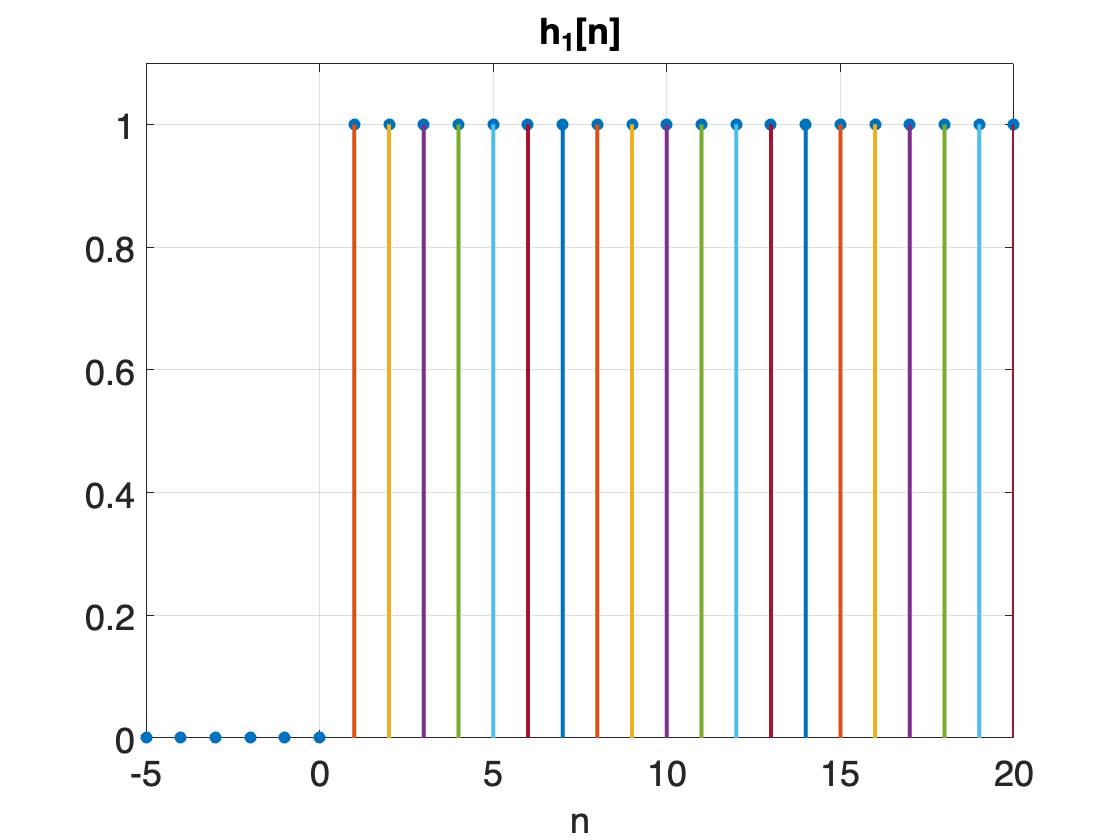

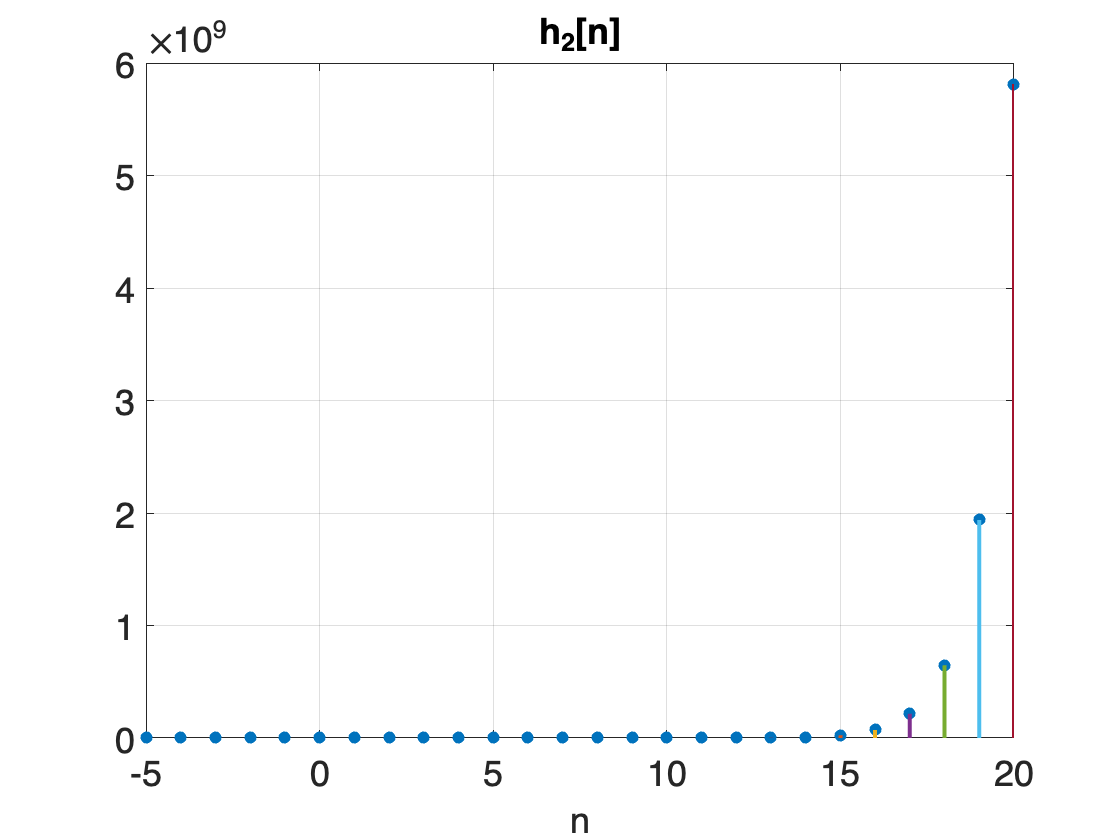

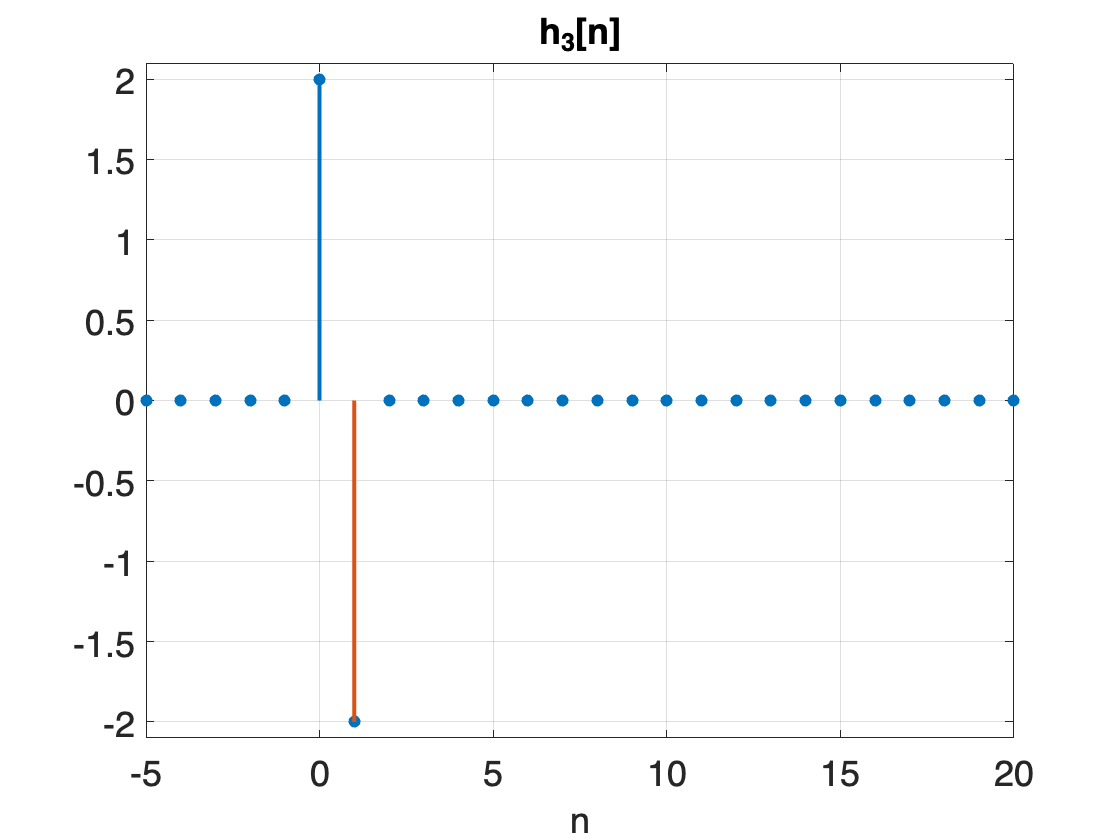

Visa_h1 = true;
Visa_h2 = true;
Visa_h3 = true;
uppgift51

Inför beräkning av impulssvaren ovan behöver man *veta* eller *anta* **kausalitetsegenskapen** för respektive system och sedan omforma varje differensekvation till ett uttryck för utsignalen $y\left\lbrack n\right\rbrack$. Detta uttryck är redan givet för system 3 och man ser direkt i systemets differensekvation vilken kausalitetsegenskap systemet har.

Vilken kausalitetsegenskap har system 3 och vilken kausalitetsegenskap har vi *antagit* för system 1 och system 2?  

☆  **Svar **(med motivering)**:**  

Vi ser att system 1 är icke-kausalt samt att system 2 och 3 är kausala. Detta kan ses i y(n$\pm$k) termerna av systemen. Om vi har y(n+k) är det icke kausalt och om vi har y(n-k) är det kausalt. 

I föregående fråga står det "Inför beräkning av impulssvaren ovan behöver man *veta* eller *anta* kausalitetsegenskapen för respektive system och sedan omforma varje differensekvation till ett uttryck för utsignalen $y\left\lbrack n\right\rbrack$". 

Omformningen sker genom att välja korrekt *y*-term i differensekvationens vänsterled som utsignal, flytta över övriga y-termer till högerledet och sedan, vid behov, justera uttrycket så $y\left\lbrack n\right\rbrack$ uttrycks som en funktion av förskjutna *x*-termer och förskjutna *y*-termer. (*För system 1 finns det till exempel två val av utsignalsterm i vänsterledet.*) Eftersom systemen är tidsinvarianta, så kan man addera och subtrahera valfritt heltal innanför "[  ]".

System 3, har bara *en* *y*-term och är därför redan uttryckt på den önskade formen.

Sätt upp det uttryck för utsignalen i system 1 respektive system 2 som gäller här, där respektive systems antagna/valda kausalitetsegenskap har gett impulssvaren $h_1 \left\lbrack n\right\rbrack$ respektive $h_2 \left\lbrack n\right\rbrack$ ovan (fyll i direkt efter "$y\left\lbrack n\right\rbrack =$"):

☆  **System 1:**  $y\left\lbrack n\right\rbrack =x\left\lbrack n-1\right\rbrack +y\left\lbrack n-1\right\rbrack \;$

☆  **System 2:**  $y\left\lbrack n\right\rbrack =5y\left\lbrack n-1\right\rbrack -6y\left\lbrack n-2\right\rbrack +8x\left\lbrack n-1\right\rbrack -19x\left\lbrack n-2\right\rbrack$

Vilken **stabilitetsegenskap** har vart och ett av de tre systemen ovan?

Motivera, utgående från impulssvarens utseende!

☆  **System 1:**  Marginellt stabilt, ty summan av integralen är oändlig, men ingen enskild term är oändlig.  

☆  **System 2:**  Instabilt, ty summan går mot oändligheten. 

☆  **System 3:**  Stabilt, ty summan av termerna går mot noll då x går mot oändligheten. 

## Uppgift 5.2 – Faltning

Nedan demonstreras tidsdiskret faltning. För insignalen $x_1 \left\lbrack n\right\rbrack =2\left(u\left\lbrack n-5\right\rbrack -u\left\lbrack n-15\right\rbrack \right)\;$beräknar och ritar skriptet utsignalen$y\left\lbrack n\right\rbrack$ från ett tidsdiskret LTI-system med impulssvar $h\left\lbrack n\right\rbrack =u\left\lbrack n-2\right\rbrack -u\left\lbrack n-6\right\rbrack \ldotp$

Klicka på knappen [Utför faltningen] nedan, så gör Matlab just detta. För att studera graferna närmare, så rekommenderas du att "lyfta ur" dem till ett separat fönster, som du kan förstora. Klicka på symbolen   längst upp till höger, strax utanför grafen i Matlabfönstret, för att erhålla samma grafer i ett separat fönster.

Jobbar lite...
Utsignalsform: 
Tidsdiskret signal


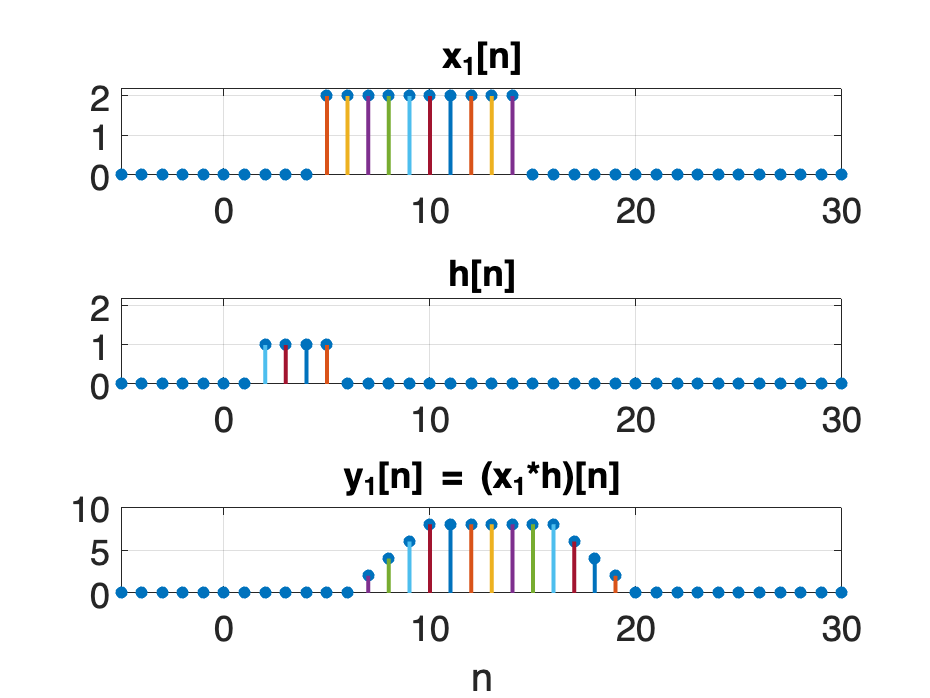

 
upg52=1; uppgift523

Varför blir utsignalen $y_1 \left\lbrack n\right\rbrack$ nollskild från och med $n=7$?

☆  **Svar:**  I formelsamlingen S.36 formel 9.5.2 ser vi att Z-transformen för det tidsinvarianta uttrycket $\delta \left\lbrack n-m\right\rbrack$ blir $z^{-m}$. När vi sedan faltar dessa får vi att $z^{-2} *z^{-5} =z^{-7}$, vilket förklarar varför grafen blir nollskild från och med n = 7. 

## Uppgift 5.3 – En systemegenskap

Nu är istället insignalen $x_2 \left\lbrack n\right\rbrack =x_1 \left\lbrack n-M\right\rbrack$, där $x_1 \left\lbrack n\right\rbrack$ är den pulsformade signalen i uppgift 5.2 ovan och du bestämmer skiftningen *M* med regeln nedan. Systemet genererar nu utsignalen $y_2 \left\lbrack n\right\rbrack$.

Variera *M* och studera resultatet. 

Jobbar lite...
Utsignalsform: 
Tidsdiskret signal


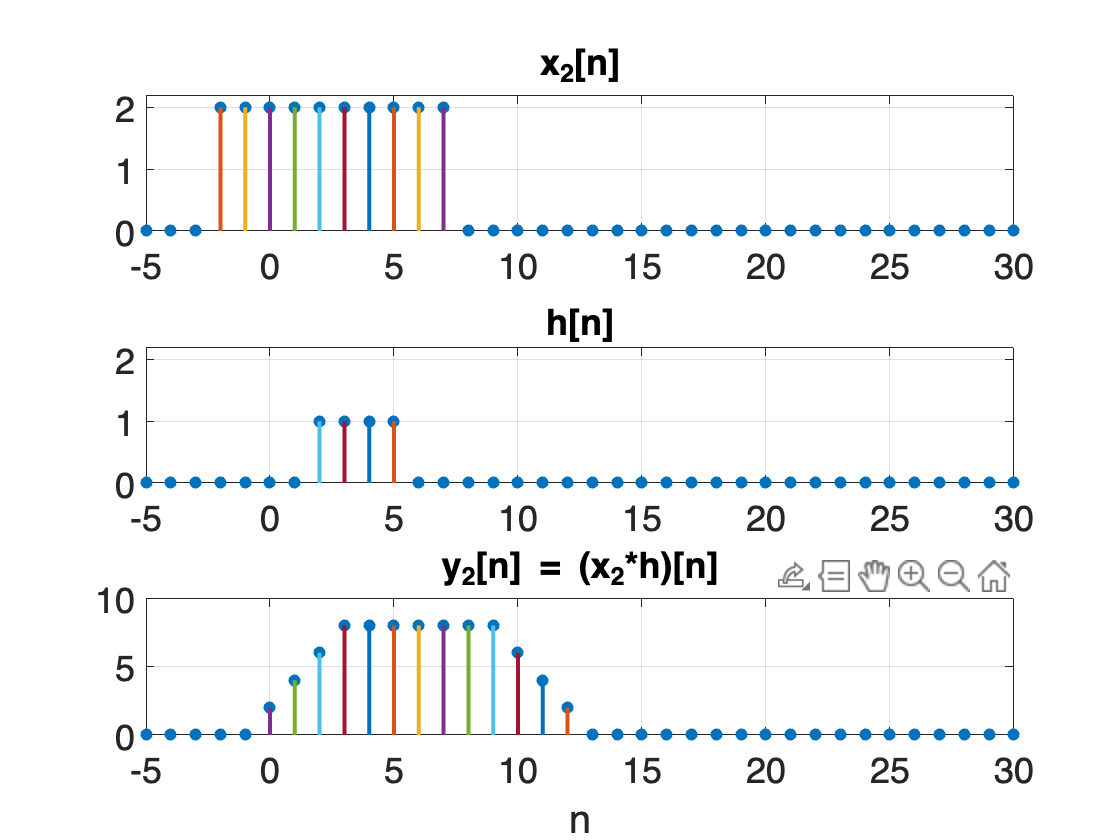

M = -7;
upg52=0; uppgift523

Vilken systemegenskap demonstreras speciellt här – dvs. då vi undersöker hur utsignalen ändras när insignalen förskjuts? Förklara!

☆  **Svar:**  Vi ser att m påverkar grafens förskjutning i sidled. Dvs, att vi efter transformering och faltning får ${y_2 \left\lbrack n\right\rbrack =\;z}^{7-m}$. Detta påvisar  systemegenskapen tidsinvarians. 

## Uppgift 5.4 – Transienta och stationära signaler

Betrakta ett nytt energifritt system, med impulssvaret $h\left\lbrack n\right\rbrack =1\ldotp 5{\left(0\ldotp 95\right)}^n \left(u\left\lbrack n\right\rbrack -u\left\lbrack n-11\right\rbrack \right)$. Bestäm, med hjälp av faltningen nedan, systemets utsignal $y\left\lbrack n\right\rbrack$ för insignalen $x\left\lbrack n\right\rbrack =\cos \left(\frac{\pi }{6}n\right)u\left\lbrack n\right\rbrack$:

Jobbar lite...
Utsignalsform: 
Tidsdiskret signal


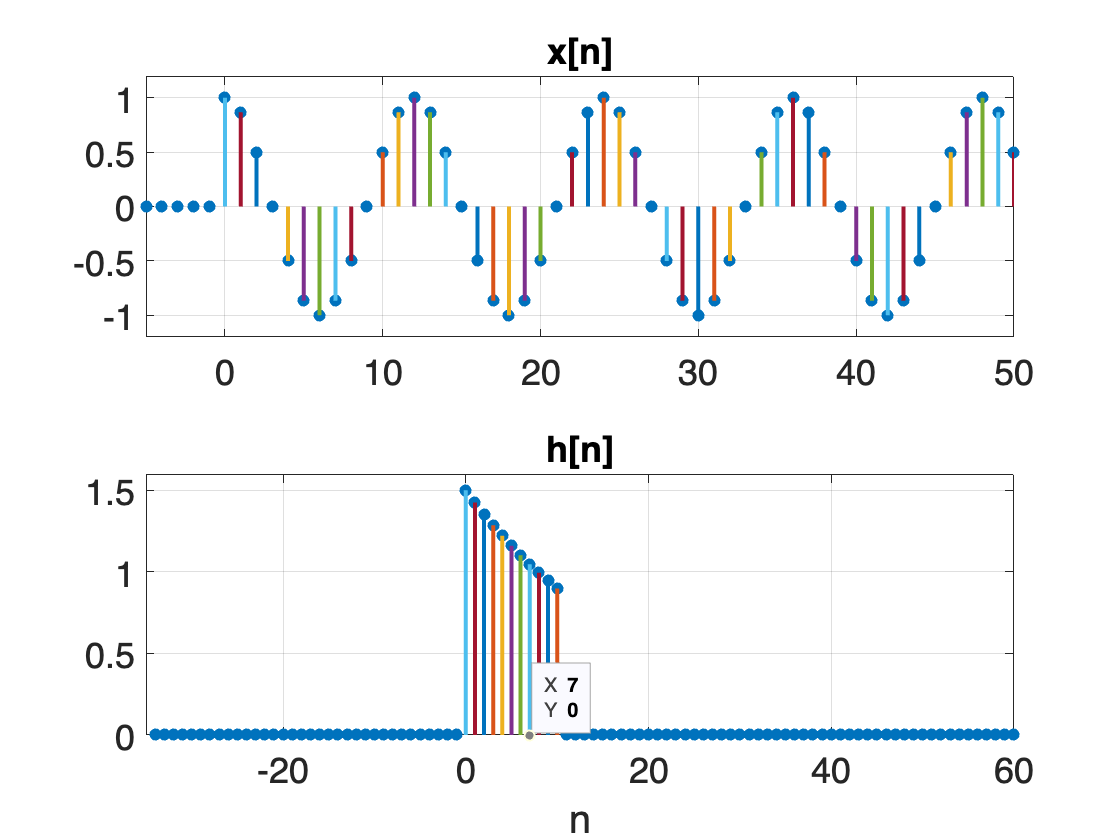

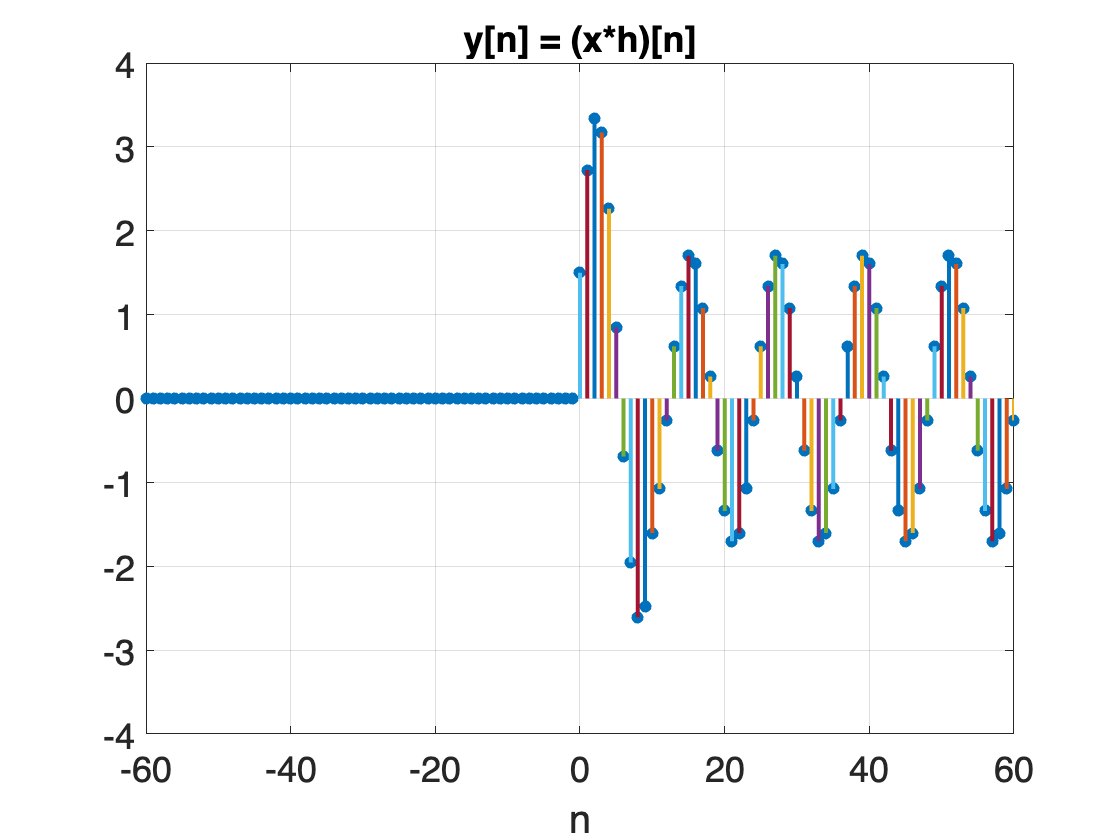

 
uppgift54

Var i den utritade grafen hittar du (syns) den *transienta* delen av utsignalen och var hittar du den *stationära* delen av utsignalen? Förklara!

☆  **Svar:**  Vi ser att $n\epsilon \left\lbrack 0,10\right\rbrack$ påverkas av någon form av störning eller brus. Detta är alltså den transienta delen av utsignalen. Vi ser enkelt att $n\;\epsilon \;\left\lbrack 11,50\right\rbrack$ är den stationära delen. Detta är logiskt då impulssvaret h[n] är nollskilt för just dessa förstnämnda n. 

# 6. Tidsdiskreta Frekvensselektiva Filter

 
startup;

 
KRETSLAB ÄR INITIERAD!
(Ett antal globala variabler är definierade)
 
För den intresserade (men behövs ej för att lösa uppgifterna):
Om du skriver 'kretslab' i kommandofönstret så öppnas ett
hjälpfönster där tollboxens funktioner är beskrivna.
 


Innan du går vidare rekommenderas du att **först titta på slutet av demonstrationsvideon för** `pzchange` (*från 17:25*) om [**hur pzchange hanterar z-transformer**](https://youtu.be/esrVNnXNMJk?t=1045)!  ⟽  Klicka på länken!

## Uppgift 6.1 – Relationen mellan *H*[*z*] och {*H*[𝜽], arg *H*[𝜽]}

Systemfunktionen $H\left\lbrack z\right\rbrack$ till ett visst amplitudnormerat kausalt tidsdiskret filter (LTI-system) har två nollställen i $z=\pm j$ och tre poler i $z=0\ldotp 9e^{\pm j\frac{\pi }{4}}$ och $z=-0\ldotp 9$.

Studera $H\left\lbrack z\right\rbrack$ och motsvarande amplitudkaraktäristik $\left|H\left\lbrack \theta \right\rbrack \right|$och faskaraktäristik $\arg \;\left|\left\lbrack \theta \right\rbrack \right|$ i `pzchange` genom att trycka på knappen [Öppna pzchange...] nedan. Följ sedan instruktionerna nedan.

- Välj ”***Rita pol-nollställevektorer ...***" i menyn ”*Pol-nollst.vektorer*” och ändra den normerade vinkelfrekvensen $\Omega_0$ mellan 0 och $\pi$ med det vertikala reglaget för att se hur amplitud- och faskaraktäristiken beror på pol- och nollställevektorerna.

- Kompletterande information/kunskap kan även erhållas från **3D-grafen av **$\left|H\left\lbrack z\right\rbrack \right|$på och innanför enhetscirkeln. Den grafen erhålls via menyvalet ”*3D-plot*”. Vrid och betrakta grafen samt reflektera över hur amplitudkaraktäristiken beror på polerna och nollställena!

Lite sidoinformation, som kan hjälpa dig att tolka och förstå:

- Tidsdiskreta funktioners fouriertransform anges antingen som funktion av  $\theta$= **normerad frekvens** (dimensionslös) eller som funktion av $\Omega =2\pi \theta$ = **normerad vinkelfrekvens **(enhet rad). 

- Notera att **fouriertransformen till tidsdiskreta funktioner är periodiska**, vilket här innebär att $H\left\lbrack \Omega \right\rbrack$ har perioden $2\pi$ rad, medan $H\left\lbrack \theta \right\rbrack$ har perioden 1. I kretslab och särskilt i `pzchange`, så visas amplitud- och faskaraktäristiken som **funktion av **$\theta$**, i intervallet 0 till 0.5** (p.g.a. spektrumets symmetri), vilket alltså motsvarar 0 till $\pi$ för $\Omega$. **Ändra dessa gränser **för den normerade frekvensen $\theta$ i edit-rutorna under faskaraktäristiken i `pzchange`, till exempel mellan –1 och +1, så du ser periodiciteten.

- Anledningen till att fouriertransformen är $2\pi$-periodisk med avseende på $\Omega$ är att **fouriertransformen är lika med z-transformen längs enhetscirkeln**. Reflektera över detta när du undersöker hur $\left|H\left\lbrack \theta \right\rbrack \right|$och $\arg \;\left|\left\lbrack \theta \right\rbrack \right|$ beror på polernas och nollställenas lägen. Jämför gärna med fouriertransformen för tidskontinuerliga funktioner – där är **fouriertransformen lika med laplacetransformen längs **$j\omega$**-axeln**, vilken *inte* är periodisk.

z-transform!


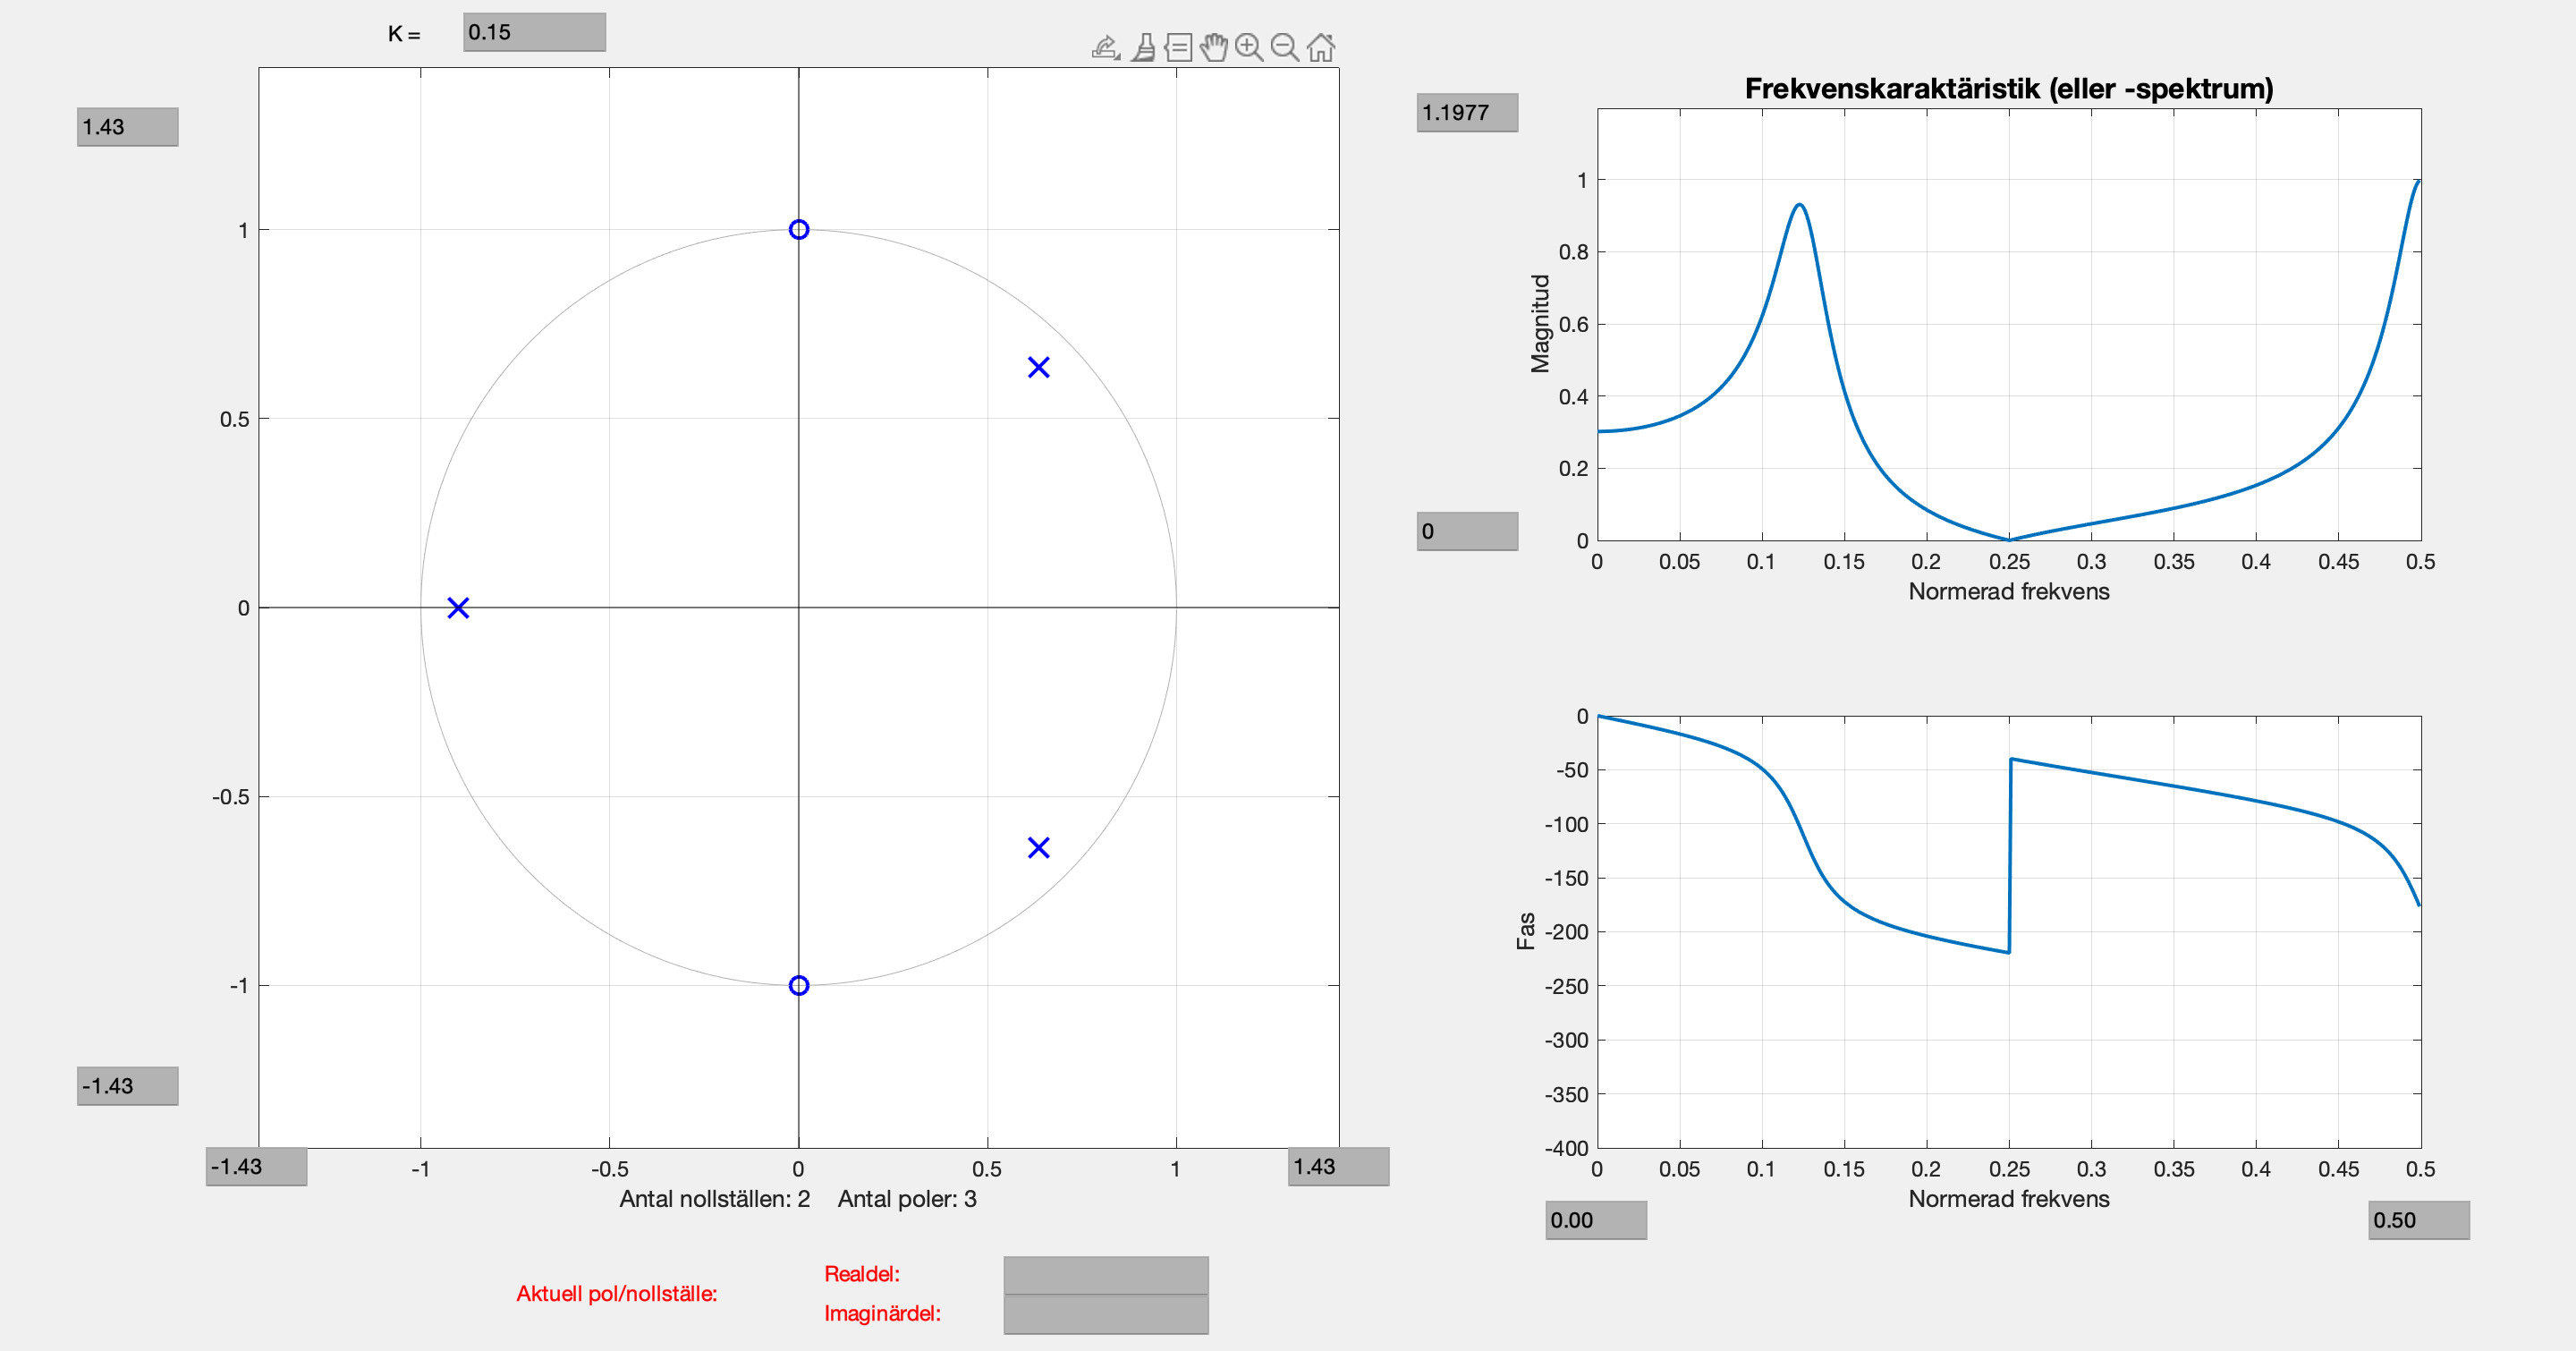

 

pzchange(in(0.1541*[1 0 1],[1 (1-sqrt(2))*[0.9 0.81] 0.9^3],'z'))

- Beskriv tydligt hur amplitudkaraktäristikens och faskaraktäristikens utseenden relateras till polernas och nollställenas lägen hos $H\left\lbrack z\right\rbrack$. 

- Förklara även varför faskaraktäristiken har en diskontinuitet vid $\theta =0,25$:

☆  **Svar:**  

För faskraktäristiken ser vi att arg(H[$\Omega$]) = arg(K) + $\sum_r \arg \left(N_r \right)-\sum_k \arg \left(P_k \right)$. Dvs att när vi flyttar nollställenas kordinater ändrar vi N-vektorn och därmed får vi diskontinuiteter i fasförskjutningen. På samma sätt påverkar P-vektorn fasförskjutningen. "När vi passerar nollställena får vi drastiska ändringar, vilket påverkar förskjutningen mycket"

Gällande frekvenskaraktäristiken ser vi att frekvensen ökar när z närmar sig en pol. Detta har att göra med utseendet för H[z], mer specifikt hur kvoten ser ut, dvs $\frac{\left(\right)\left(\right)}{\left(\right)\left(\right)\left(\right)}$. 

## Uppgift 6.2 – FIR-filter och IIR-filter

Två olika tidsdiskreta LTI-system ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{A}}}$ och ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{B}}}$ utgör båda *amplitudnormerade*, *kausala* och *stabila *tidsdiskreta **LP-filter** med normerad 3 dB-gränsfrekvens $\theta_0 \approx 0\ldotp 15$ (dvs. de har samma normerade 3 dB-gränsvinkelfrekvens $\Omega_0 \approx 0\ldotp 3\pi \;\textrm{rad}$).

Med hjälp av `pzchange` ska du nedan skapa systemfunktionerna $H_A \left\lbrack z\right\rbrack$ respektive $H_B \left\lbrack z\right\rbrack$ för dessa två LTI-system, genom att placera ut poler och nollställen på lämpliga ställen i z-planet.

### Uppgift 6.2a

Här ska du inledningsvis skapa systemfunktionen $H_A \left\lbrack z\right\rbrack$ för LTI-system ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{A}}}$ och utöver kriterierna ovan ska följande gälla:

- $H_A \left\lbrack z\right\rbrack$ får ha *godtyckligt* placerade poler.

- Systemets ordning (antal poler hos $H_A \left\lbrack z\right\rbrack$) ska vara *så låg som möjligt*, men max 2.

Innan du börjar skapa både $H_A \left\lbrack z\right\rbrack$ och $H_B \left\lbrack z\right\rbrack$, så behöver du reflektera över relationen mellan antalet poler och nollställen i systemfunktionerna:

Vilket krav finns det på relationen mellan *antalet* poler och nollställen för kausala tidsdiskreta LTI-system?

☆  **Svar:**  

För att systemet ska vara stabilt måste antalet poler$\le$ antal nolltsällen.

Om du tidigare har skapat och längre ner sparat din systemfunktion $H_A \left\lbrack z\right\rbrack ,$ kan du ladda in den i Matlab här igen:

 
alt=1; uppgift62a

 
Systemfunktionen H_A[z] är hämtad!


Klicka här för att starta `pzchange` – med din tidigare $H_A \left\lbrack z\right\rbrack$, om du har hämtat den till Matlab, eller för att skapa den:

z-transform!


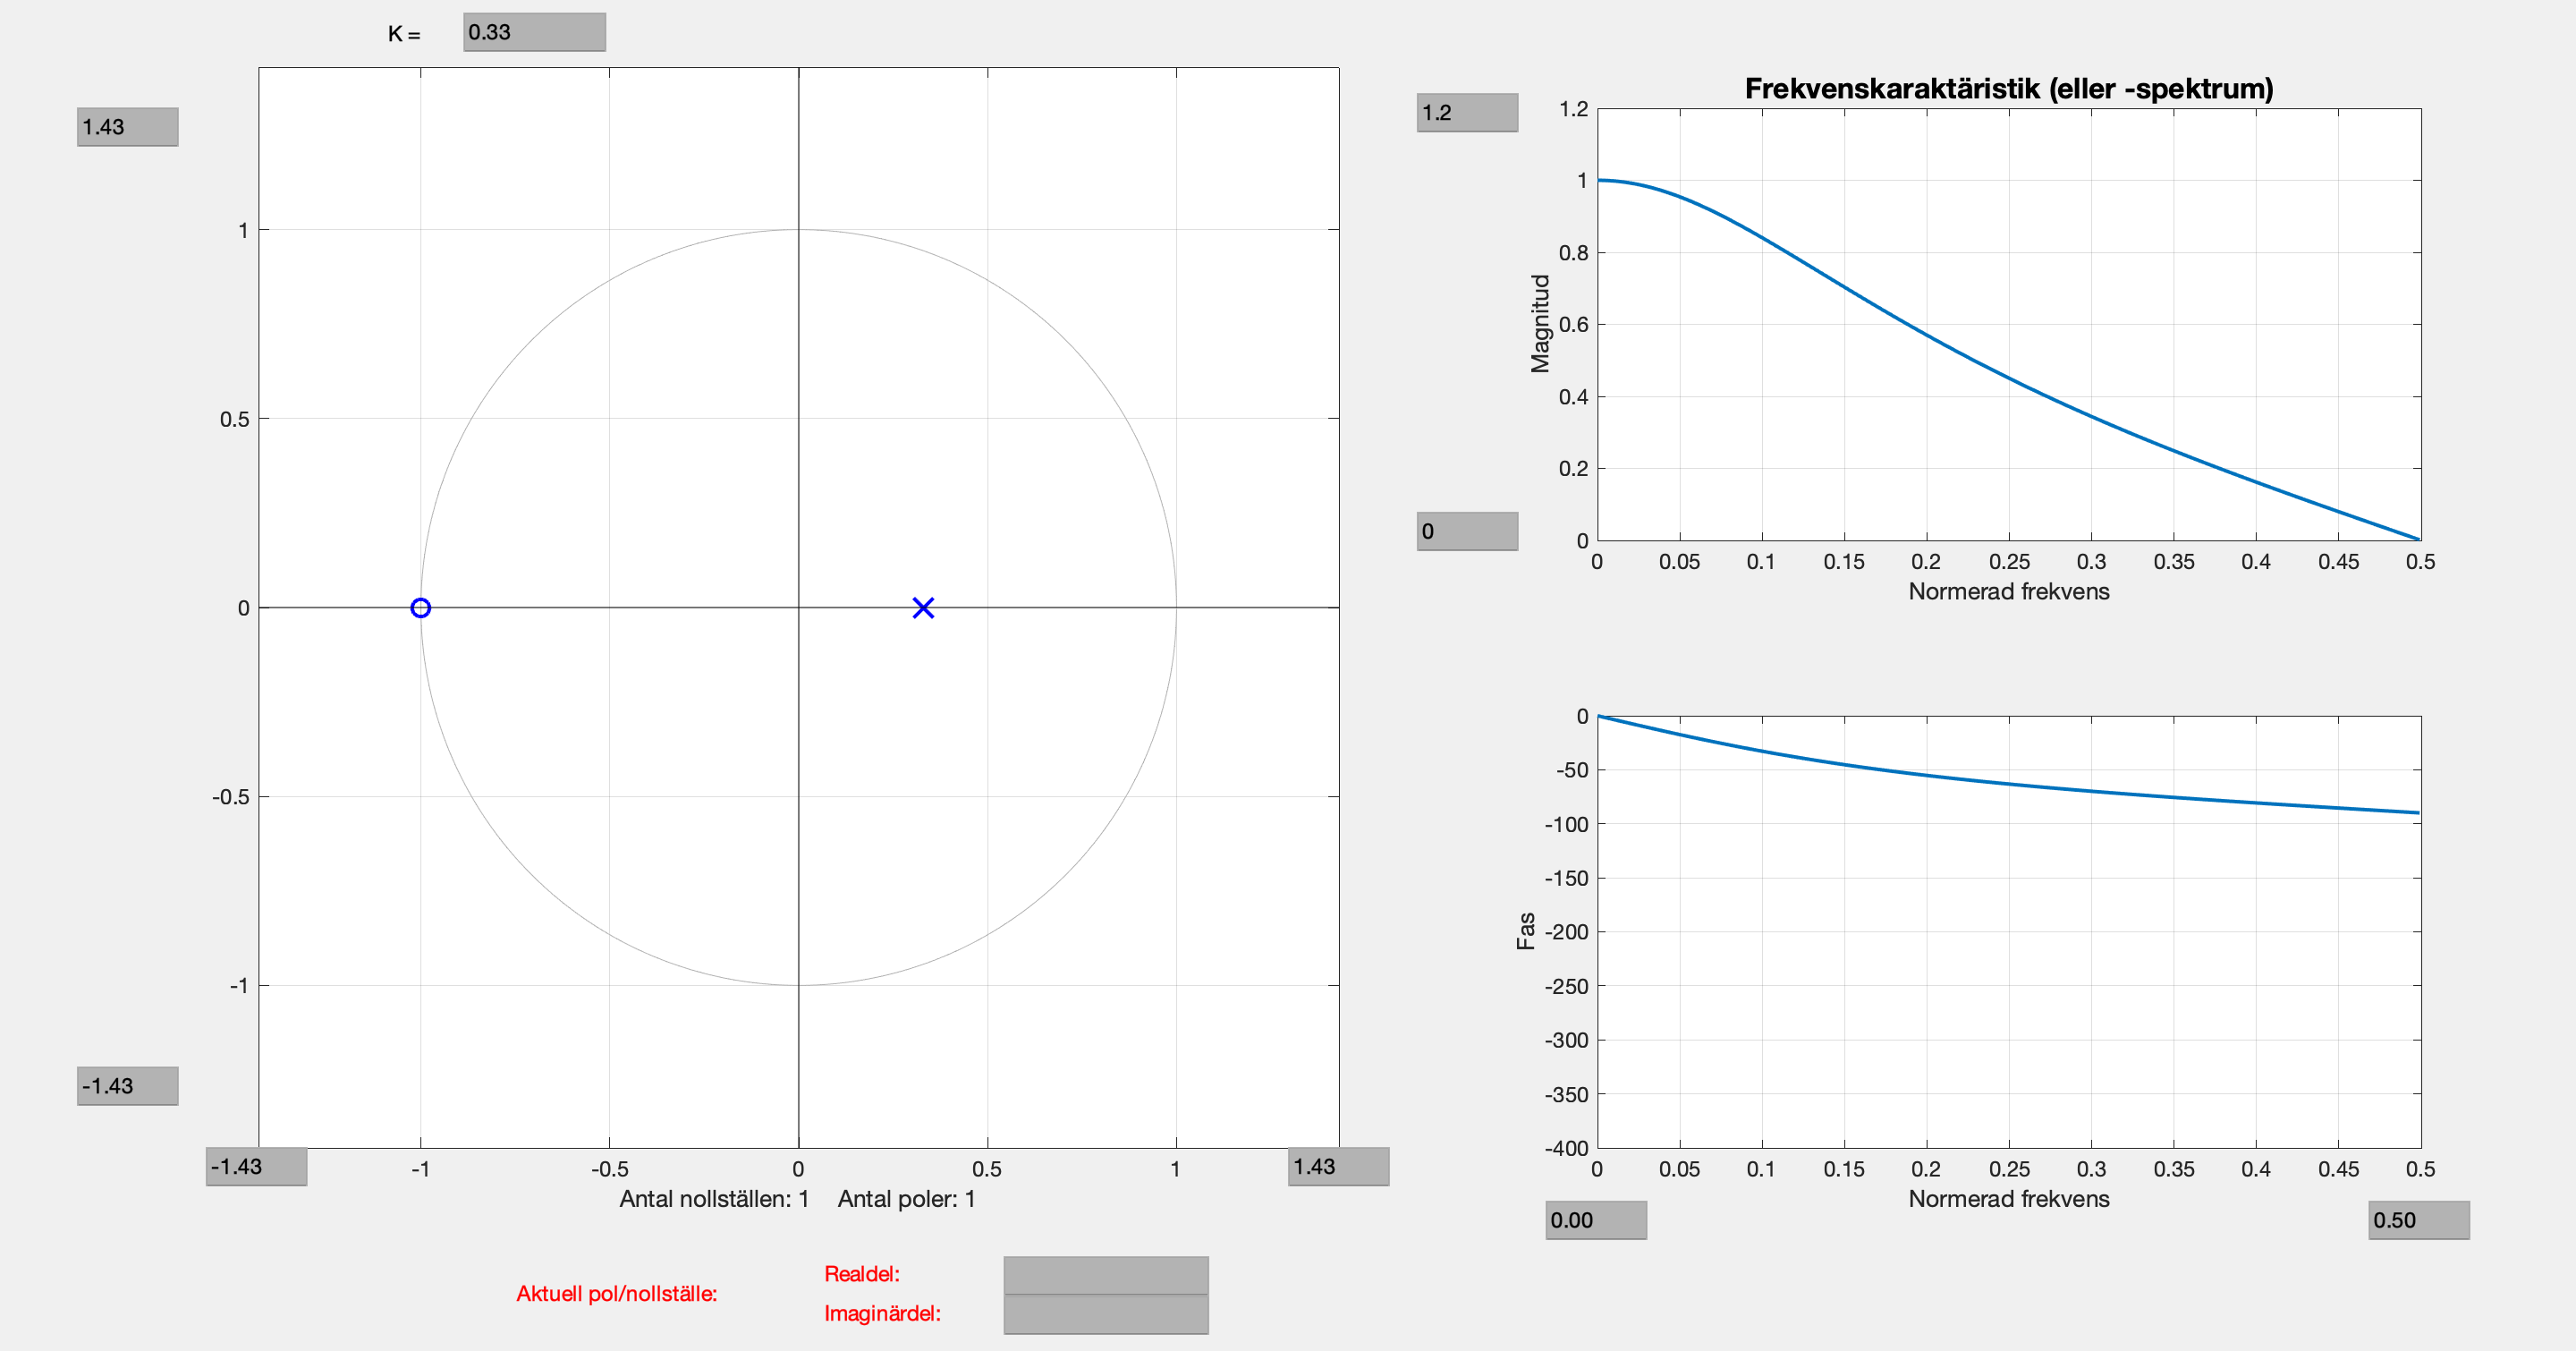

 
alt=2; uppgift62a

När du i `pzchange `är klar med din filterdesign, så klickar du på knappen [Spara H_A[z]] nedan. Då sparas din systemfunktion som variabeln H_A i datafilen Uppgift62a.

***OBS****: Gör detta ****innan**** du startar *`pzchange`* igen, för *`pzchange`* kan bara hantera ****en transform i taget****!! (Transformen lagras som den globala variabeln TRMF.)*

 
alt=3; uppgift62a

 
Din systemfunktion H_A[z] är sparad!


Redovisa din erhållna systemfunktion $H_A \left\lbrack z\right\rbrack$ nedan. 

Skriv då täljar- och nämnarpolynomen på *faktoriserad* form, med nollställena och polerna på *polär form*, dvs. som t.ex. $H\left\lbrack z\right\rbrack =3\cdot \frac{\left(z+0\ldotp 2\right)}{\left(z-0\ldotp 8e^{\textrm{j1}\ldotp 22} \right)\left(z-0\ldotp 8e^{-\textrm{j1}\ldotp 22} \right)}$ :

☆  **Svar:**  $H_A \left\lbrack z\right\rbrack =0\ldotp 33\frac{\left(z+1\right)}{\left(z-0\ldotp 33\right)}\;$

Motivera tydligt* antalet *poler och nollställen samt deras *placeringar*!

☆  **Svar:**  

I denna lösning har vi ett nollställe respektive en pol, se stabila krav från 6.2 a). Placeringen av nollställen sker utifrån föreläsningsslidesen. Placeringen av polen görs enligt anteckning på Ipad:

Vi vet att den lilla cirkeln kommer ha radien $\omega_p$ samt att den efterfrågade polen kommer ligga någonstans på cirkelbanan. Om vi beräknar $\omega_p =\frac{\Omega_0 }{\sqrt{2}}=\frac{0\ldotp 3\pi }{\sqrt{2}}=0\ldotp 66$, vi får då att realdelen av polens kordinat är 1 - 0.66 = 0.33. Re{z}=0.33 medför att Im{z} = 0. Alltså får vi $z=0\ldotp 33+0j$

### Uppgift 6.2b

Nu ska du skapa systemfunktionen $H_B \left\lbrack z\right\rbrack$ för LTI-system ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{B}}}$ och utöver kriterierna i inledningen av Uppgift 6.2 ska $H_B \left\lbrack z\right\rbrack$ uppfylla följande:

- $H_B \left\lbrack z\right\rbrack$ måste ha alla sina poler placerade i *origo*.

- Systemets ordning (antal poler hos $H_B \left\lbrack z\right\rbrack$) ska vara *så låg som möjligt*, men max 2 – dvs. samma krav som för $H_A \left\lbrack z\right\rbrack$.

Om du tidigare har skapat och längre ner sparat din systemfunktion $H_B \left\lbrack z\right\rbrack ,$ kan du ladda in den i Matlab här igen:

 
alt=1; uppgift62b

 
Systemfunktionen H_B[z] är hämtad!


Klicka här för att starta `pzchange` – med din tidigare $H_B \left\lbrack z\right\rbrack$, om du har hämtat den till Matlab, eller för att skapa den:

z-transform!


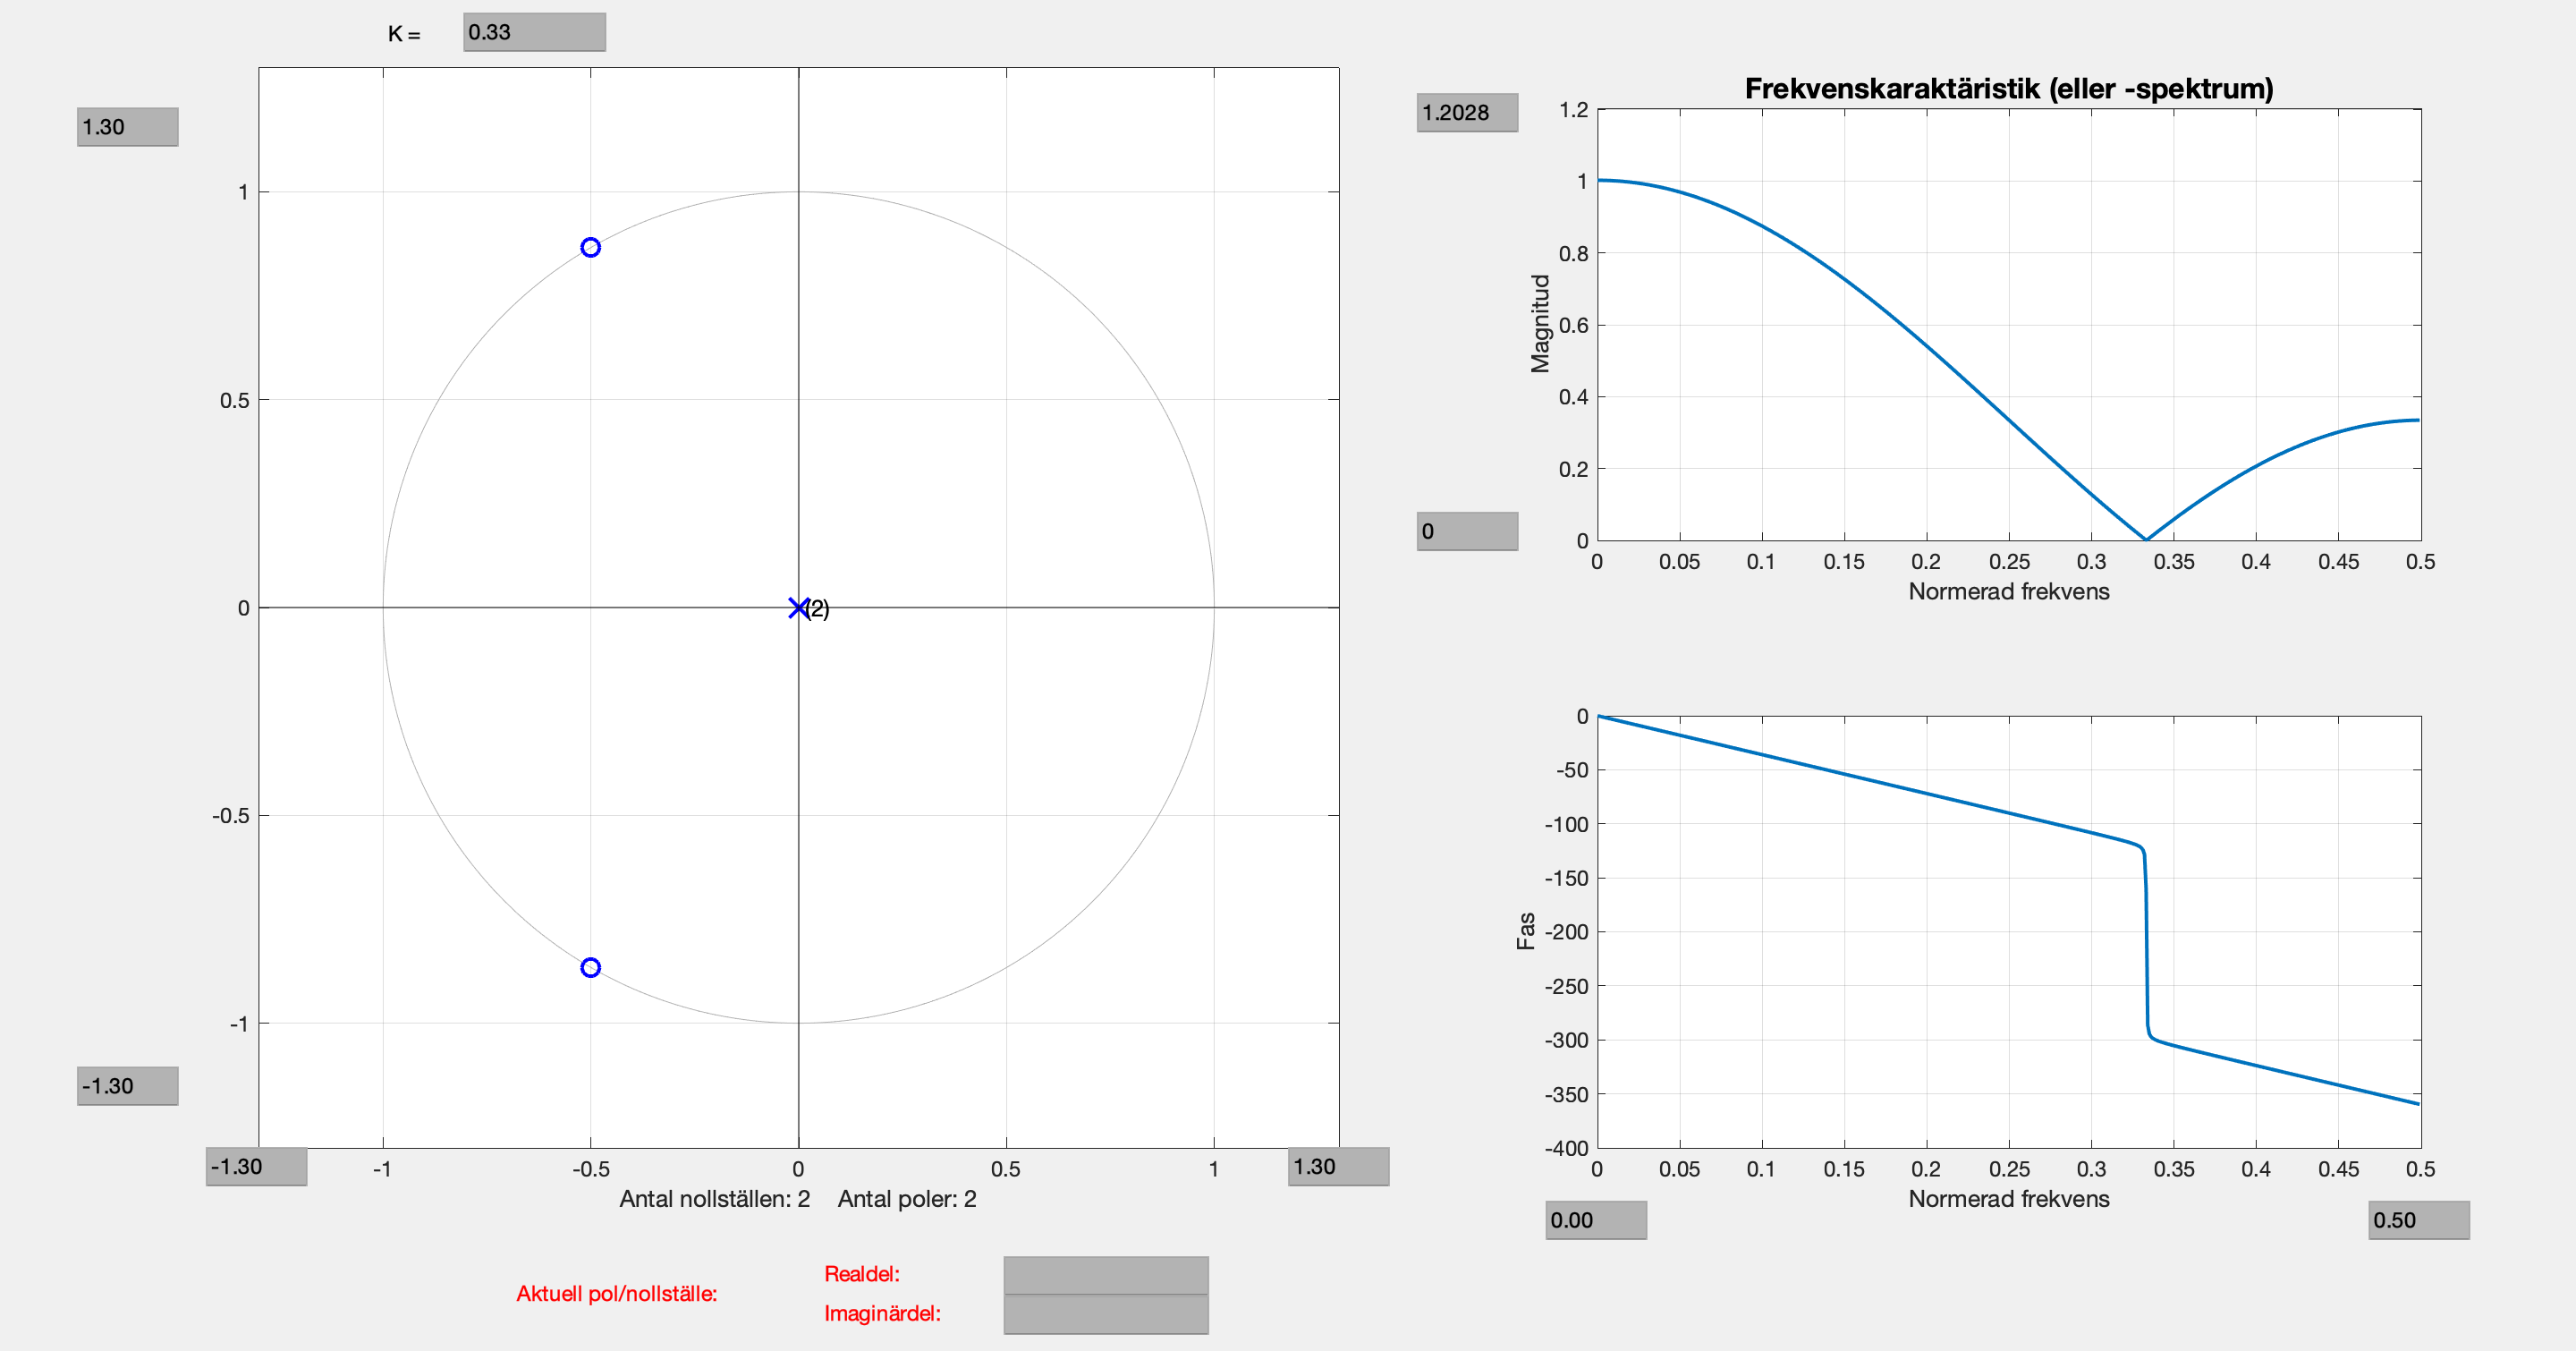

 
alt=2; uppgift62b

När du i `pzchange `är klar med din filterdesign, så klickar du på knappen [Spara H_B[z]] nedan. Då sparas din systemfunktion som variabeln H_B i datafilen Uppgift62b.

 
alt=3; uppgift62b

 
Din systemfunktion H_B[z] är sparad!


Redovisa din erhållna systemfunktion $H_B \left\lbrack z\right\rbrack$ nedan. 

Liksom för $H_A \left\lbrack z\right\rbrack$, så ska du ange täljar- och nämnarpolynomen på *faktoriserad* form, med nollställena och polerna på *polär form*:

☆  **Svar:**  $H_B \left\lbrack z\right\rbrack =0\ldotp 33\frac{\left(z+0\ldotp 5\right)e^{0\ldotp 86738j} }{z^2 }\;$

Motivera även här tydligt* antalet *poler och nollställen samt deras *placering(ar)*!

☆  **Svar:**  Vi testade oss fram, bara gudarna vet hur man räknar sig fram till detta. 

### Uppgift 6.2c

Nedan kan du markera vilka grafer du vill se och jämföra med varandra – det är pol-nollställediagrammen för dina systemfunktioner $H_A \left\lbrack z\right\rbrack$ och $H_B \left\lbrack z\right\rbrack$, amplitudkaraktäristikerna ${\left|H_A \left\lbrack \theta \right\rbrack \right|}_{\textrm{dB}}$ och ${\left|H_B \left\lbrack \theta \right\rbrack \right|}_{\textrm{dB}}$ (dvs. i dB-skala) samt impulssvaren $h_A \left\lbrack n\right\rbrack$ och $h_B \left\lbrack n\right\rbrack$.

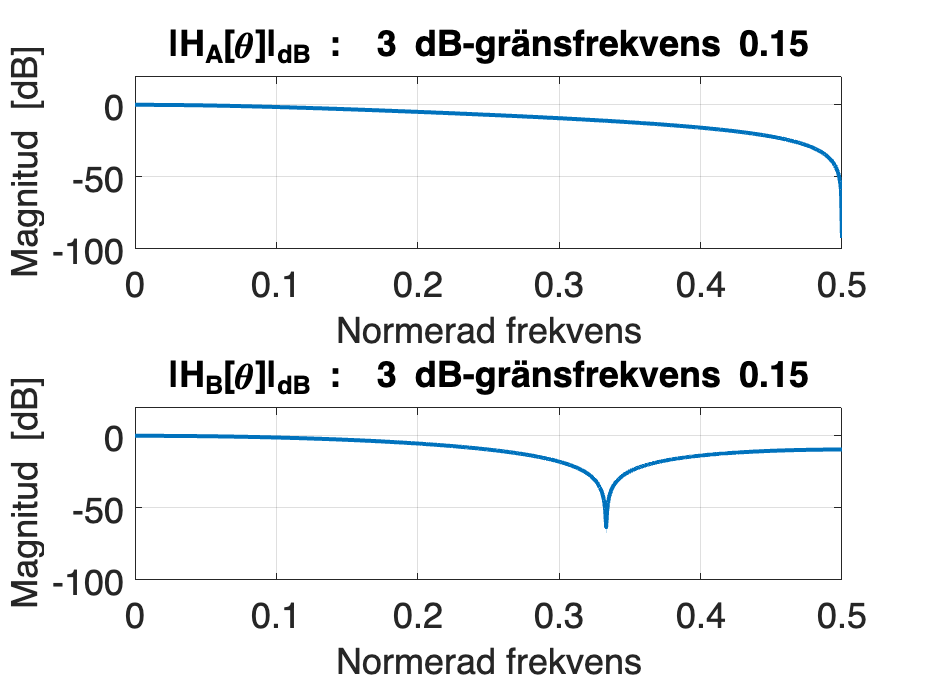

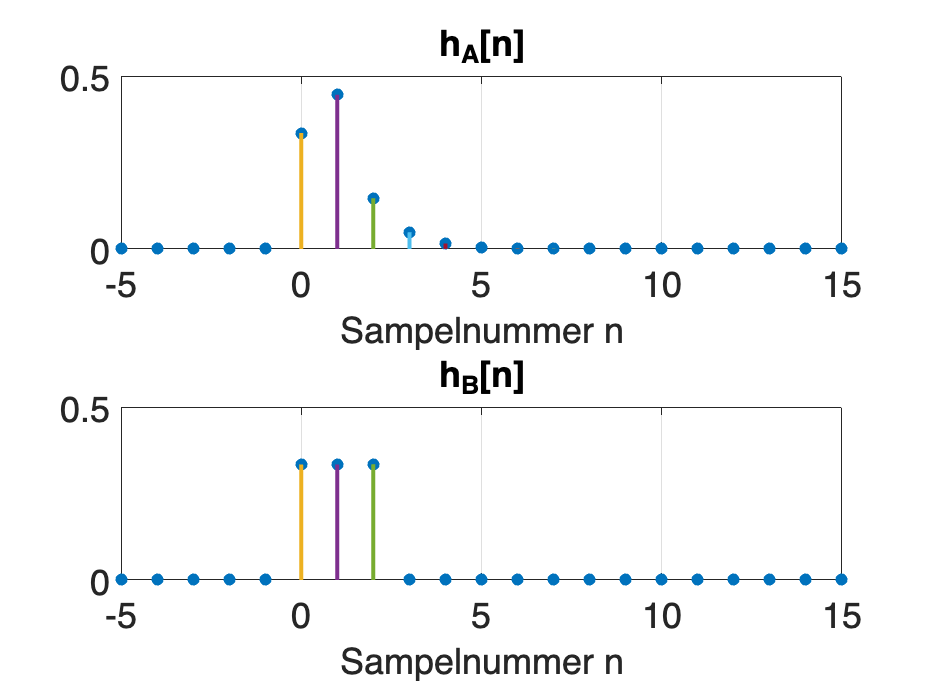

H_AB = false;    % Visa pol-nollställediagrammen för H_A[z] och H_B[z]
ABS_AB = true;  % Visa |H_A[𝜃]| och |H_B[𝜃]| i dB-skala 
h_AB = true;    % Visa impulssvaren h_A[n] och h_B[n]
uppgift62c

Jämför dina två LP-filter med varandra, i termer av filterordning, dämpningsegenskaper, m.m. Redovisa dina slutsatser och eventuella för- och nackdelar med de olika filterna: 

☆  **Svar:**  Vi ser att ${\mathit{\mathbf{H}}}_A$ aldrig når värdet noll då N -> 15, till skillnad från ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{B}}}$ som når Y = 0, vilket är logiskt med tanke på skillnaden mellan FIR och IIR filter. Vi ser också att ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{B}}}$ är av ordning 2 och ${\mathit{\mathbf{H}}}_A$ är av ordning 1. 

### Uppgift 6.2d

Det finns olika typer av klassificeringar för tidsdiskreta filter. Exempelvis utgör varje tidsdiskret filter antingen ett **FIR-filter** eller ett **IIR-filter**. Detta är två begrepp som alla med grundläggande kunskaper i tidsdiskret (digital) signalbehandling förväntas att känna till. Exempelvis är ett av dina två filter, ${\mathit{\mathbf{H}}}_A$ eller ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{B}}}$, ett **FIR-filter** och det andra är ett **IIR-filter**.

Här är en [**video med en tydlig och bra sammanfattning av FIR-filter och IIR-filter**](https://youtu.be/9yNQBWKRSs4) (⟽  *klicka på länken*) – **se den!** För att svara på frågorna nedan, så räcker det att du ser den första delen på 3:35 minuter, men du rekommenderas att gärna se hela videon! (*Du kan även läsa lite om FIR- och IIR-filter i kursboken, till exempel i avsnittet "MATLAB SESSION 5" i slutet av kapitel 5, men videon sammanfattar det viktigaste mycket bra*.)

- **0:00 – 3:35   ⟹ En *****översiktlig*** ***jämförelse *****mellan FIR-filter och IIR-filter.**

- 3:35 – 6:15   ⟹ Skillnad i *realisering* mellan FIR- och IIR-filter.

- 6:15 – 12:27 ⟹ *Filterdesignperspektiv* när man vill approximera ett IIR-filter med ett FIR-filter.

Vilka är de huvudsakliga skillnaderna mellan FIR-filter och IIR-filter – i transformdomänen och i tidsdomänen?

☆  **Svar:**  

**Transformdomän:**

FIR-filter har en ändlig impulssvarslängd, vilket innebär att dess impulssvar blir noll efter en viss tid. IIR-filter har en oändlig impulssvarslängd, vilket innebär att dess impulssvar kan fortsätta på obestämd tid.

**Tidsdomän:**

FIR-filter är alltid stabila eftersom dess poler ligger i origo i Z-transformen. Detta innebär att alla dess poler är inuti enhetscirkeln. IIR-filter kan vara stabila eller instabila beroende på placeringen av dess poler. 

Vilket av dina två filter ${\mathit{\mathbf{H}}}_A$ och ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{B}}}$ ovan är ett FIR-filter och vilket är ett IIR-filter? Motivera!

☆  **Svar:**  ${\mathit{\mathbf{H}}}_A$ är ett IIR filter och ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{B}}}$ är ett FIR filter, ty att vi inte har några poler i nämnaren i ${\mathit{\mathbf{H}}}_{\mathit{\mathbf{B}}}$. 

## Uppgift 6.3 – Tidsdiskreta Butterwortfilter & Chebyshevfiler

I Laboration 3 undersökte du skillnader mellan *tidskontinuerliga *butterworthfilter och chebyshev-filter. I den här uppgiften ska du på motsvarande sätt undersöka skillnader mellan *tidsdiskreta* butterworthfilter och chebyshev I-filter, å ena sidan filter av lågpasstyp och å andra sidan av högpasstyp.

Ange nedan

- Vilken **filtertyp** du vill studera (lågpass- eller högpassfilter).

- Filtrens **gradtal** (mellan 1 och 10).

- Eventuell ändrad **övre gräns **på frekvensintervallet för ritade $\left|H\left\lbrack \theta \right\rbrack \right|$.

- **Övre gräns **på *n*-intervallet för ritade $h\left\lbrack n\right\rbrack$.

Markera sedan vilka grafer du vill visa. Graferna ändras därefter när du ändrar något i kontrollerna eller klickar på knappen "Visa markerade grafer".  

- Studera gärna grafer närmare i ett fristående större fönster, genom att klicka på symbolen   längst upp till höger om figuren. Du kan till exempel använda detta för att *studera skillnader mellan filter* av olika gradtal eller filtertyp, för om du sedan genererar nya grader så ändras *inte* några fristående fönster. 

- Notera att det kan ta lite tid att beräkna och rita graferna, beroende på hur snabb din dator är.

filtertyp = "low";
N = 10;      % Filtrets gradtal
fmax = 0.5;  % Övre normerad frekvensgräns för ritade |H[𝜃]|
nmax = 30;   % Övre tidsgräns för ritade h[n]

 
PZ = true;                    % Visa pol-nollställediagrammen
AM = 2;     % Visa amplitudkaraktäristikerna
dBmin = 1;  % Ändra eventuellt undre gräns på dB-skalan
hn = true;                   % Visa impulssvaren
uppgift631

*Alla nollställena till dessa filter ska – för bästa spärrbandsdämpning – hamna antingen i *$z=-1$*eller *$z=1$*, beroende på om det är lågpassfilter eller högpassfilter du studerar. På grund av Matlabs beräkningsonoggrannhet så hamnar dock nollställena strax utanför dessa punkter i z-planet när gradtalet ökar. Zooma gärna själv in mot nollställena och studera var de hamnar*.

### Uppgift 6.3a

Jämför och kommentera kortfattat de båda **lågpassfiltrens** allmänna *likheter och skillnader* m.a.p. pol-nollställediagram, amplitudkaraktäristik och impulssvar.  Reflektera även över dessa likheter och skillnader och varför graferna "ser ut som de gör" för respektive filter.

☆  **Svar:**  Vi ser att butterworth-filtret har sina poler placerade i en halvcirkel riktad mot origo, medans chebyshev har en halvcirkel riktad från origo. Vi ser också att chebyshev har ett visst brus utanför bandbredd, detta har inte butterworth. Å andra sidan har chebyshev en snabbare övergång från bandbredd till utfiltrerade frekvenser, vilket är eftertraktat i vissa applikationer. 

### Uppgift 6.3b

Jämför och kommentera kortfattat de båda **högpassfiltrens** almänna* likheter och skillnader *m.a.p. pol-nollställediagram, amplitudkaraktäristik och impulssvar.  Reflektera även över dessa likheter och skillnader och varför graferna "ser ut som de gör" för respektive filter.

☆  **Svar:**  Vi ser att chebyshev har sina poler i formen av en elips och butterworth i formen av en halvcirkel riktad mot origo. Fördelen med chebyshevs polplacering är att man får en skarpare övergång från utfiltrerade frekvenser och igenomsläppta frekvenser. Detta möjligörs av det varierande distanserna mellan polerna i chebyshevs pol-nolltsälle diagram. 

## Uppgift 6.4 – Tidsdiskret Bandpassfiltrering av en DTMF-signal

I Uppgift 3.3 i Laboration 2 undersökte du frekvensegenskaperna för den *tidskontinuerliga* signalen `toner`, som består av en sekvens med DTMF-pulser. I Uppgift 4.6 i Laboration 3 filtrerade du sedan denna signal med ett **tidskontinuerligt bandpassfilter**, som du själv hade designat. 

Som du redan vet från Uppgift 3.3, så utgör `toner` egentligen en *samplad* version (65536 sampelvärden, sampelfrekvens $f_s =$ 6400 Hz) av en motsvarande tidskontinuerlig signal, för *Matlab kan ju inte lagra tidskontinuerliga signaler*. Antal sampelvärden definieras av matlabvariabeln `KlabL` $\left(2^{16} =65536\right)$ och maximal sampelfrekvens definieras av varabeln `FSMAX` $\left(2^7 \cdot 50=6400\right)\ldotp$ De 65536 första elementen i Matlab-vektorn `toner` innehåller sampelvärdena (där position `KlabL`/2+1 = 32769 innehåller värdet för *t* = 0) och `toner(65537)` innehåller sampelperioden $T=\frac{1}{f_s }$.

*Om du vill experimentera med andra värden någon gång, så kan du vid annat tillfälle ändra dessa variabler. Låt i så fall *`KlabL`* vara en 2-potens (för snabba fouriertransformberäkningar med DFT!) och låt ****FSMAX ****vara en 2-potens gånger 50*. *Ändra detta **efter** att du först initierat Kretslab med *`startup`.

En **tidsdiskret signal **$x\left\lbrack n\right\rbrack$ lagras å andra sidan i Kretslab som en vektor med 65536+4 = 65540 värden, där de `KlabL` = 65536 första värdena är signalens värden symmetriskt runt $n=0$, där $x\left\lbrack 0\right\rbrack$ finns i vektorelement `KlabL`/2+1 = 32769. (*Intresserade studenter kan läsa mer om hur Kretslab representerar olika signaler och transformer genom att skriva *`help vartype`* i kommandofönstret*.)

Under resten av Uppgift 6.4 låter vi den tidskontinuerliga signalen $x\left(t\right)$vara lika med `toner` (dvs. $x\left(t\right)=$ `toner`) och vi låter den tidsdiskreta signalen $x\left\lbrack n\right\rbrack$ vara lika med `Dtoner` (dvs. $x\left\lbrack n\right\rbrack =x\left(\textrm{nT}\right)=$ `Dtoner`). 

När du klickar på knappen [Undersök toner] nedan, så sker följande:

- Den samplade *tidskontinuerliga* signalen `toner` från datafilen `dtmf` och den använda sampelperioden *T* sparas i variabeln `T`. 

- Rita den första DTMF-pulsen i `toner`.

- Rita *början *av den första DTMF-pulsen `toner` i ett mindre tidsintervall $-5T\le t\le 30T,$ dvs. motsvarande 36 sampelpunkter.

- Markera sampelvärdena i `toner` med "O".

- Skapa en vektor `Dtoner` genom att lägga till tre godtyckliga element (nollor här) i slutet av vektorn `toner`. Därigenom tolkar Kretslab `Dtoner` som en *tidsdiskret *signal (se texten ovan om hur Kretslab representerar olika signaltyper).

- Rita den *tidsdiskreta *signalen `Dtoner` i motsvarande intervall som `toner`, dvs. för $-5\le n\le 30\ldotp$

Skriv gärna `type uppgift641` i kommandofönstret för att se matlabkoden för ovanstående!

 
uppgift641

**Studera** de två graferna och **reflektera** över hur tidskontinuerliga signaler – i det här fallet `toner`, representeras i Kretslab!

### Uppgift 6.4a

Nedan kan du rita amplitudspektrumet $\left|X\left(f\right)\right|$ för den tidskontinuerliga signalen $x\left(t\right)=$ `toner` och amplitudspektrumet $\left|X\left\lbrack \theta \right\rbrack \right|$ för den tidsdiskreta signalen $x\left\lbrack n\right\rbrack =x\left(\textrm{nT}\right)=$ `Dtoner`, för att jämföra dessa med varandra. Vid markering av rutan nedan, så ändras frekvensgränserna så du ser det intressanta frekvensområdet bättre. Du kan förstås även själv zooma in manuellt i graferna.

 
ZoomaIn = false;  % Markera för att zooma in i grafen, närmare frekvenskomponenterna
uppgift64a

Var och en av frekvenskomponenterna i $\left|X\left(f\right)\right|$ (med 7 olika frekvenser) har motsvarande frekvenskomponenter i $\left|X\left\lbrack \theta \right\rbrack \right|$ vid olika *normerade* frekvenser samt med andra amplituder. 

Ange det allmänna sambandet mellan frekvenser $f$ och normerade frekvenser $\theta$ som gäller här, dvs. ett uttryck för den *frekvensskalning *som sker vid samplingen:

☆  **Svar:**  $\theta =\frac{f_c }{f_s }$ där $f_c$ är den kontinuerliga frekvensen i Hz, $f_s$ är den samplade frekvensen i Hz.

Ange även vilket samband som råder mellan amplituderna hos $\left|X\left(f\right)\right|$ och $\left|X\left\lbrack \theta \right\rbrack \right|$, dvs. ett uttryck för den *amplitudskalning *som sker vid samplingen:

☆  **Svar:**  $k=\frac{X\left\lbrack \theta \right\rbrack }{X\left\lbrack f\right\rbrack }=6400$

Varför är $\left|X\left(f\right)\right|$ och $\left|X\left\lbrack \theta \right\rbrack \right|$ bara ritade upp  till $f=3200$ Hz respektive $\theta =0\ldotp 5$? Hur ser dessa amplitudspektra ut för högre frekvenser? 

☆  **Svar:**  Intervallet 0.5 till 1 är en direkt spegling av 0 - 0.5 i den normerade domänen. 

### Uppgift 6.4b

I stället för att, som i Laboration 3, filtrera $x\left(t\right)=$ `toner` med ett *tidskontinuerligt* bandpassfilter, så kan man filtrera  $x\left\lbrack n\right\rbrack =x\left(\textrm{nT}\right)=$ `Dtoner` genom ett motsvarande *tidsdiskret* bandpassfilter. Som en sista laborationsuppgift ska du ta fram och undersöka ett sådant tidsdiskret BP-filter samt jämföra dess egenskaper med motsvarande tidskontinuerliga filter. 

De krav vi har på det tidskontinuerliga amplitudnormerade bandpassfiltret är att frekvenskomponenterna hos $x\left(t\right)$ vid $f_{\textrm{p1}} =941\;\textrm{Hz}$ och $f_{\textrm{p2}} =1209\;\textrm{Hz}$ inte får dämpas med mer än 3 dB och dämpningen vid $f_{\textrm{s1}} =900\;\textrm{Hz}$ och $f_{\textrm{s2}} =1250\;\textrm{Hz}$ skall vara *minst* 6 dB. Dessa filterkrav illustreras av följande graf, som du känner igen från föreläsningarna om frekvensselektiva filter, där amplitudkaraktäristiken ${\left|H\left(f\right)\right|}_{\textrm{dB}}$ *inte* får gå genom något av de streckade områdena:

             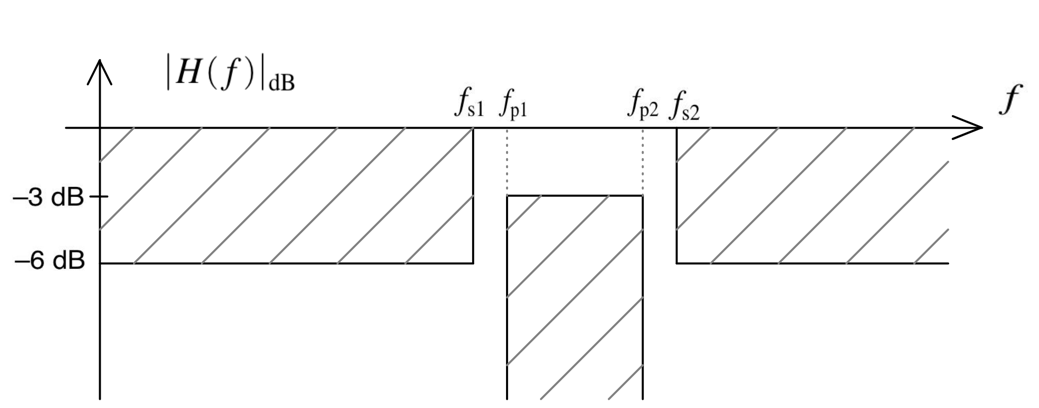

Samma dämpningskrav gäller därför för det tidsdiskreta bandpassfiltrets amplitudkaraktäristik ${\left|H\left\lbrack \theta \right\rbrack \right|}_{\textrm{dB}}$ vid motsvarande *normerade* frekvenser $\theta_{\textrm{p1}}$, $\theta_{\textrm{p2}}$, $\theta_{\textrm{s1}}$ respektive $\theta_{\textrm{s2}}$:

              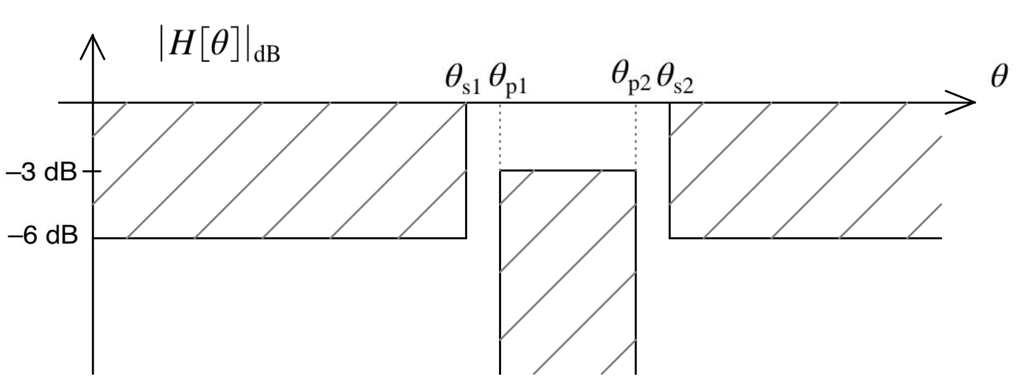

Ange värdena på det tidsdiskreta BP-filtrets två motsvarande normerade 3 dB-gränsfrekvenser i nedanstående textfält (*det räcker med tre decimaler*). Klicka sedan på knappen [Spara gränsfrekvenser], så att Kretslab sedan kan använda *dina* normerade gränsfrekvenser för att syntetisera/skapa det tidsdiskreta BP-filtret. 

(*Du får en röd feltext om något av fälten är tomma. Därför står det värden där, som du ska ändra till de korrekta normerade gränsfrekvenserna.*)

Ange BP-filtrets *undre *normerade gränsfrekvens $\theta_{\textrm{p1}\;}$**: **

**941/6400  = 0.147**

**1209/6400 = 0.189 **

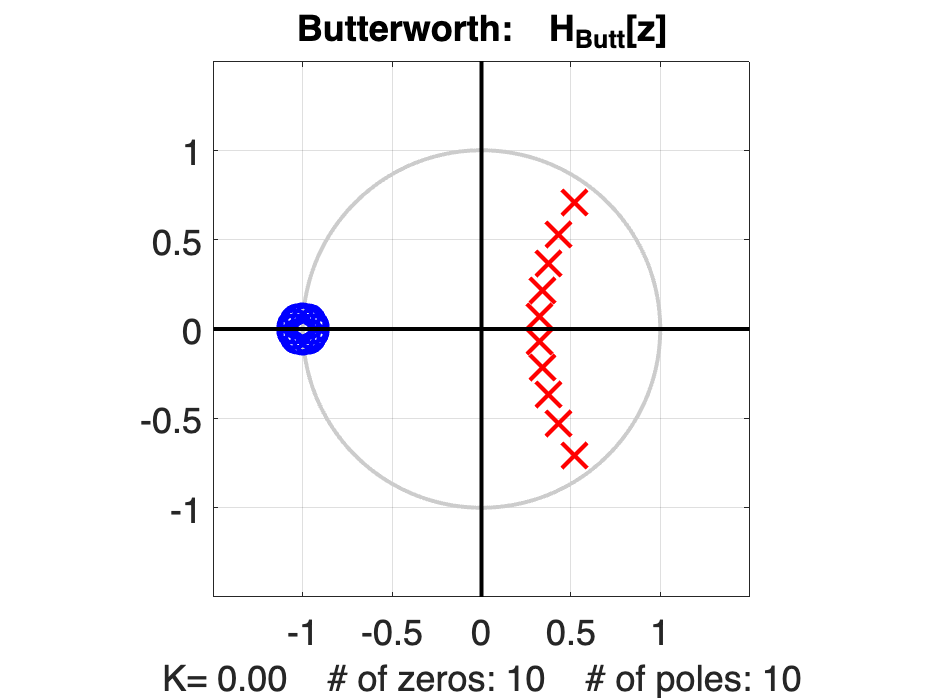

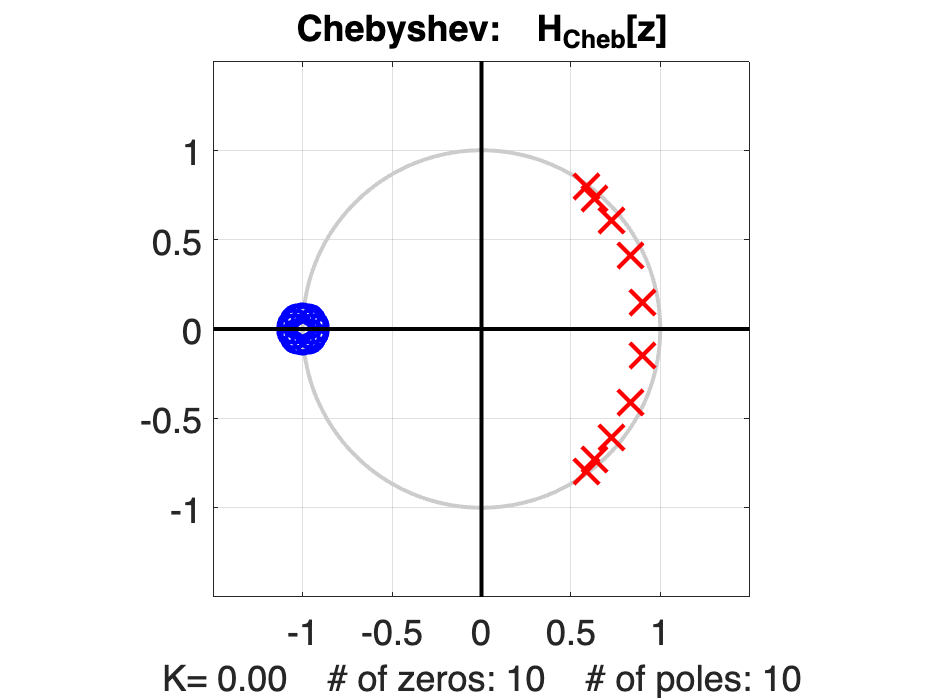

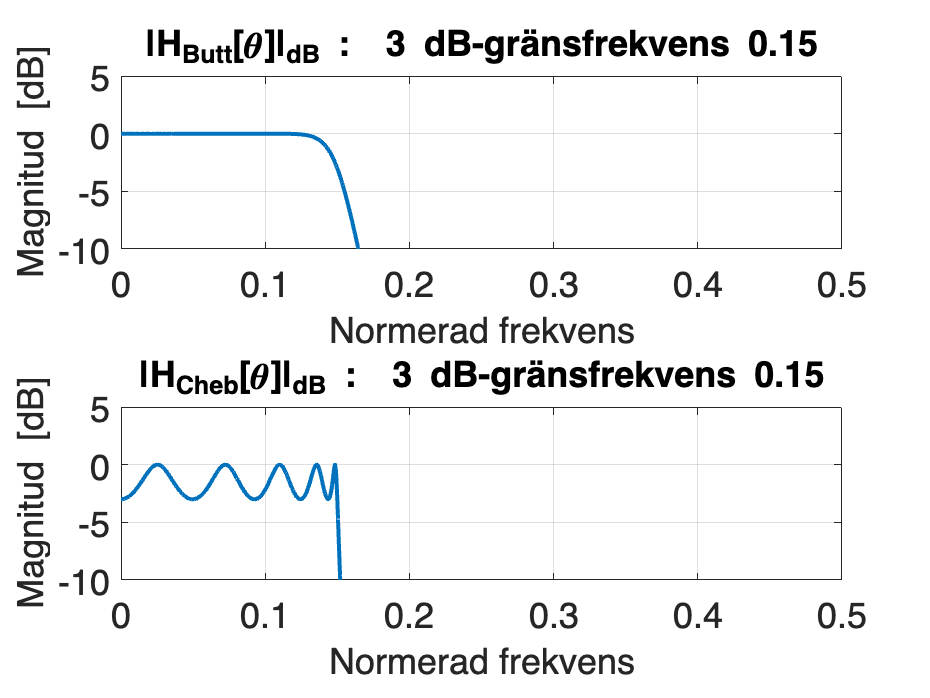

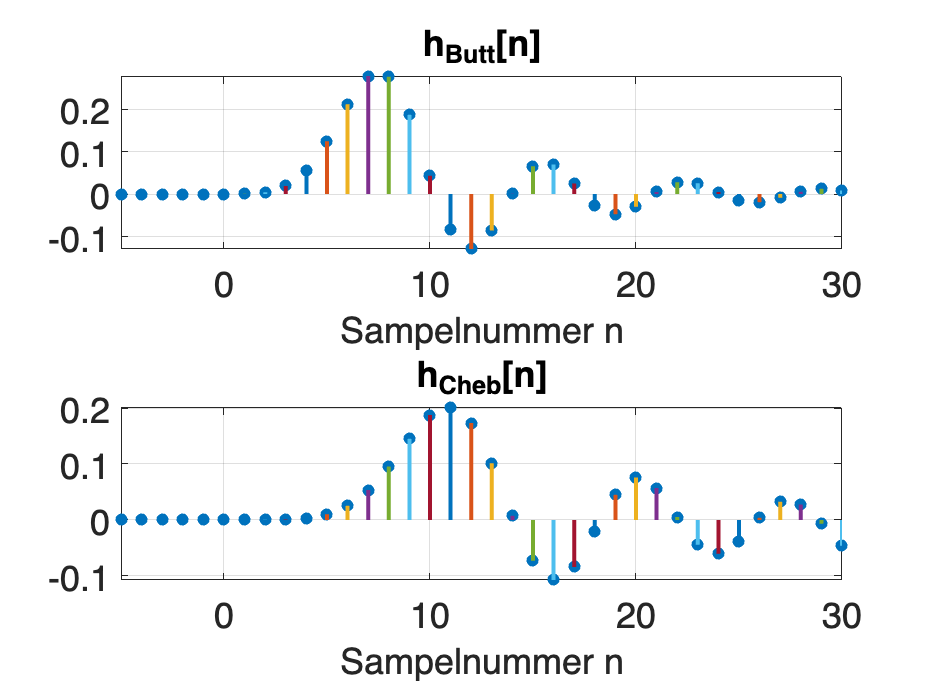

thetaP1 = 0.147;

Ange BP-filtrets *övre *normerade gränsfrekvens $\theta_{\textrm{p2}} \;$:

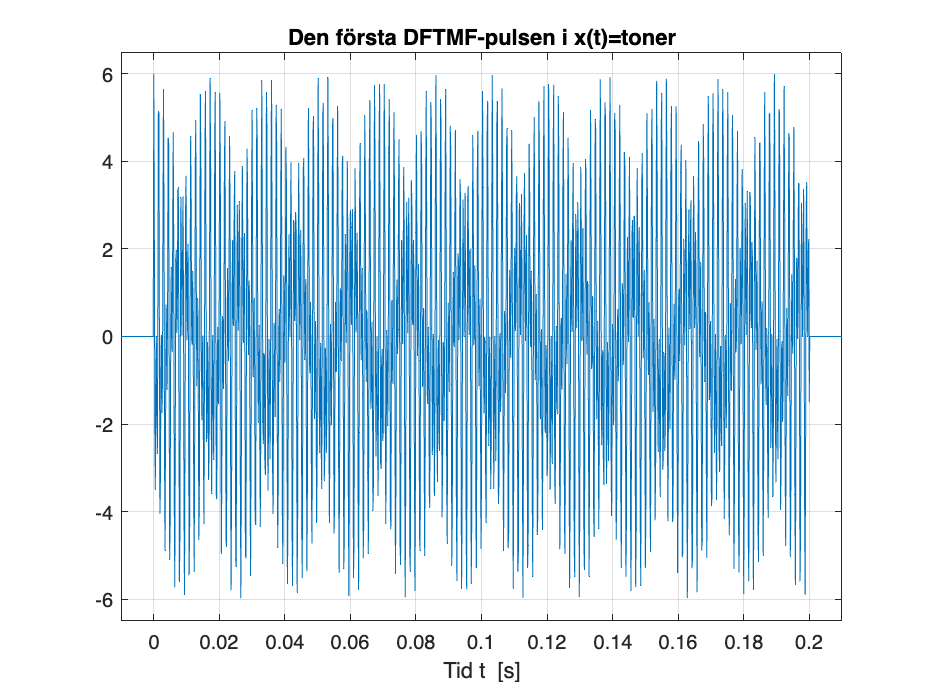

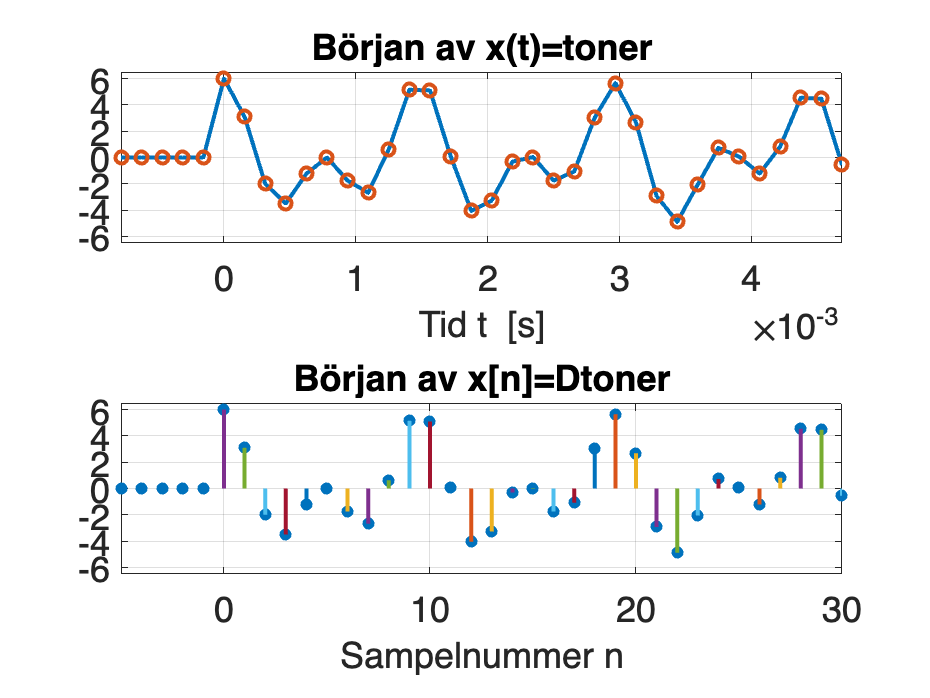

thetaP2 = 0.189;

 
uppgift64c0

### Uppgift 6.4c

Vid konstruktionen av det *tidskontinuerliga* filtret i Laboration 3 fick ordningen, dvs. antalet poler, vara högst 6. Om man använder ett **chebyshev I-filter**, så är det möjligt att uppfylla dämpningskraven med ett filter med endast *4 poler*.

Nedan genereras två **chebyshev I-bandpassfilter** av ordning 4:

- Det ena, med systemfunktion $H\left(s\right)$, är ett *tidskontinuerligt* BP-filter med 3 dB-gränsfrekvenserna $f_{\textrm{p1}} =941\;\textrm{Hz}$ och $f_{\textrm{p2}} =1209\;\textrm{Hz}\ldotp$

- Det andra, med systemfunktion $H\left\lbrack z\right\rbrack$, är ett *tidsdiskret* BP-filter, med motsvarande *normerade *3 dB-gränsfrekvenserna $\theta_{\textrm{p1}}$ och $\theta_{\textrm{p2}}$. Vid filterkonstruktionen används de värden som du själv matade in här ovan, så det är förstås viktigt att du matar in rätt värden

Klicka på knappen nedan för att skapa $H\left(s\right)$ och $H\left\lbrack z\right\rbrack$ enligt ovan.

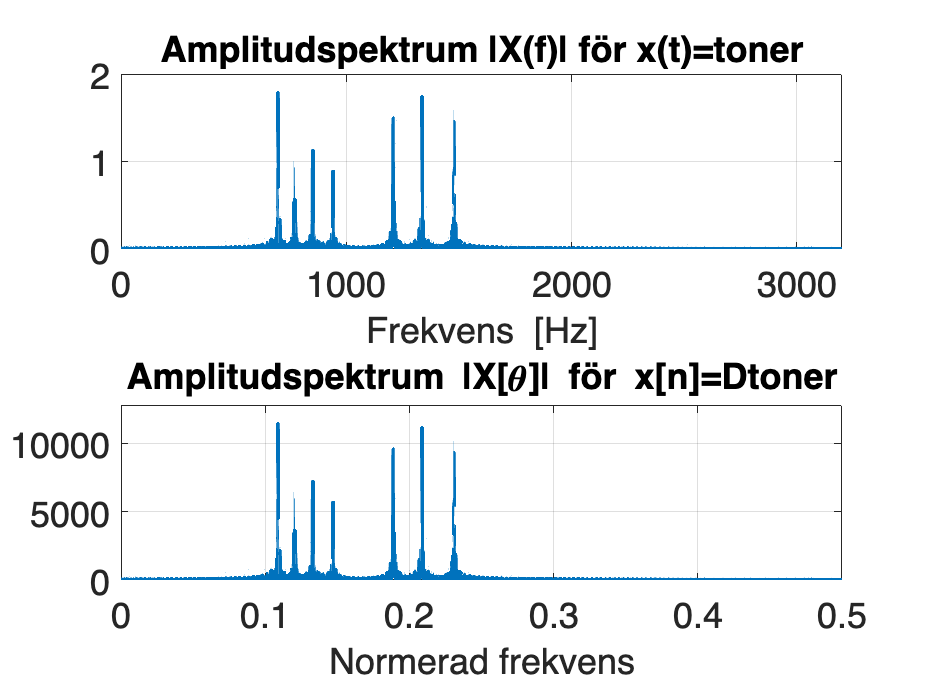

uppgift64c1

Markera nedan vilka grafer du vill visa och **undersök sedan systemens respektive pol-nollställediagram och amplitudkaraktäristik** – som kan visas både i linjär skala och i dB-skala. Vid jämförelsen bör du tänka på att det normerade frekvensintervallet 0 till 0.5 för $\left|H\left\lbrack \theta \right\rbrack \right|$ motsvarar frekvensintervallet 0 till $\frac{f_{\mathrm{s}} }{2}=3200\;\textrm{Hz}$ för$\left|H\left(f\right)\right|$. 

Lyft gärna ur graferna till fristående fönster för att kunna studera graferna närmare!

Du kan även öppna `pzchange` med antingen $H\left(s\right)$eller $H\left\lbrack z\right\rbrack$för att se både pol-nollställediagram och amplitudkaraktäristiken i samma figurfönster – se sista alternativet nedan.

PNs = true;          % Visa pol-nollställediagrammet för H(s)
PNz = true;          % Visa pol-nollställediagrammet för H[z]
AMli = true;         % Visa/jämför filtrens amplitudklaraktäristik i linjär skala 
AMdB = true;         % Visa/jämför filtrens amplitudklaraktäristik i dB-skala
uppgift64c2

pzHsz = 2;

Gränsfrekvenserna sparade!


Systemfunktionerna är skapade!
 


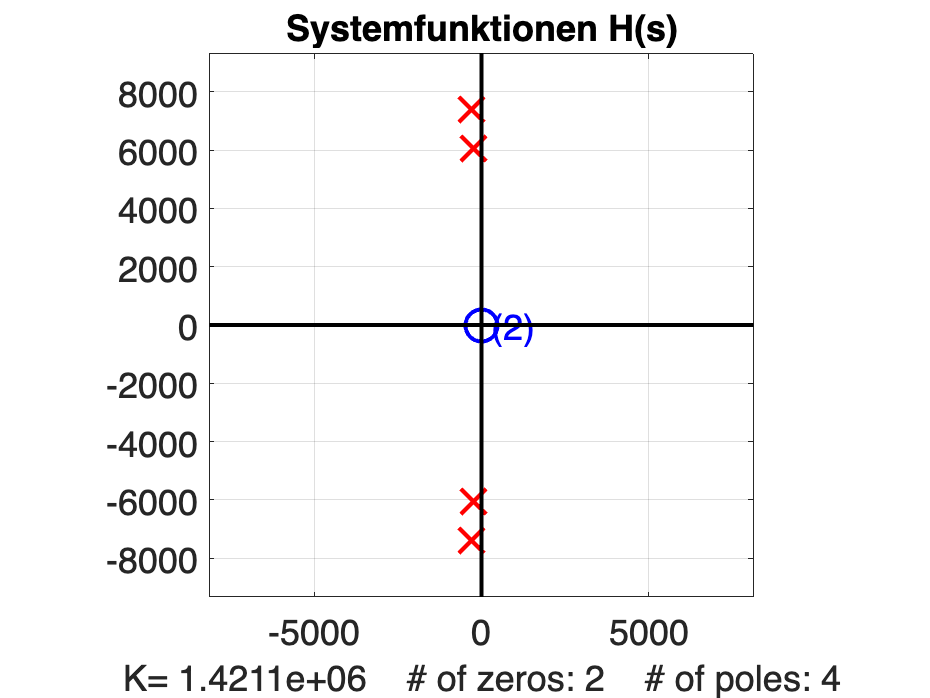

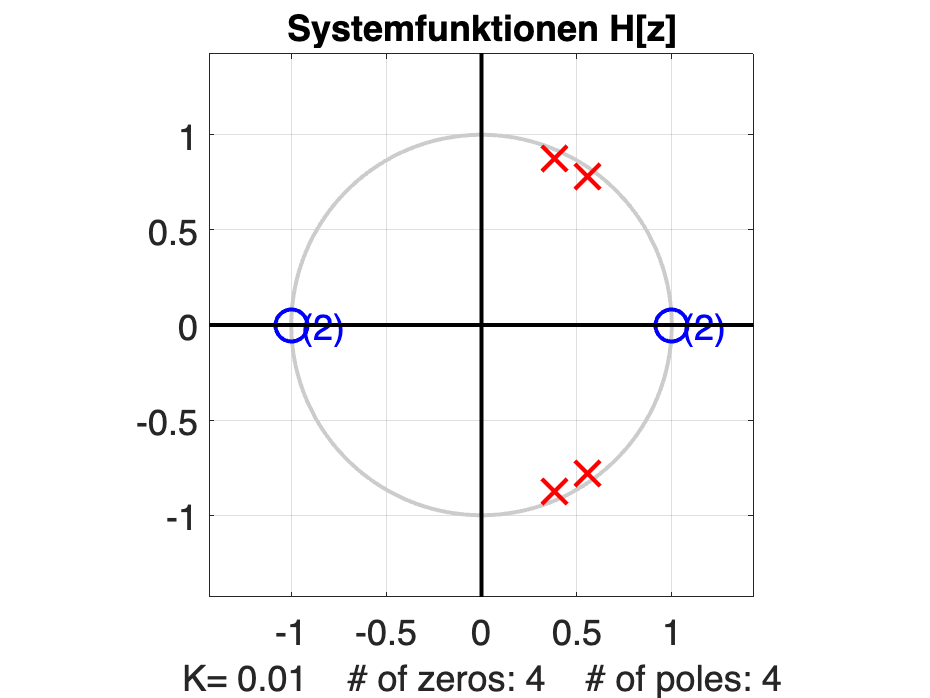

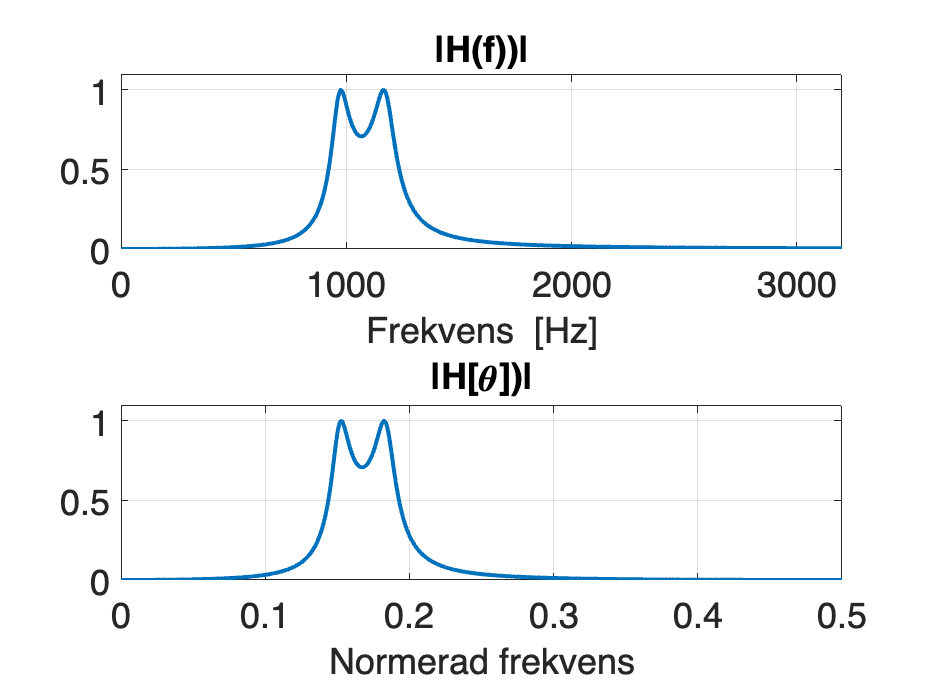

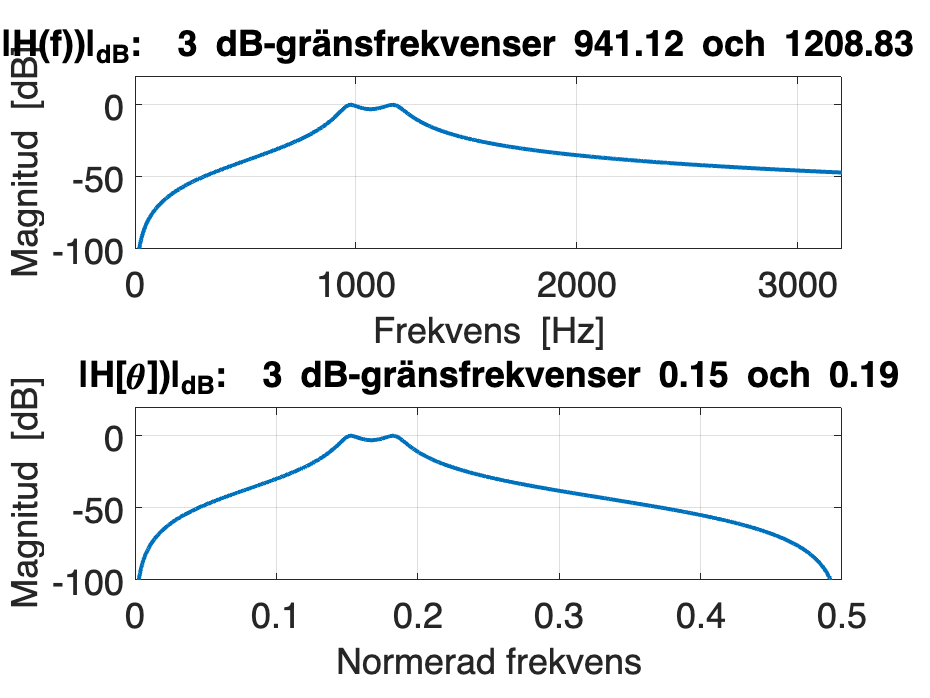

z-transform!


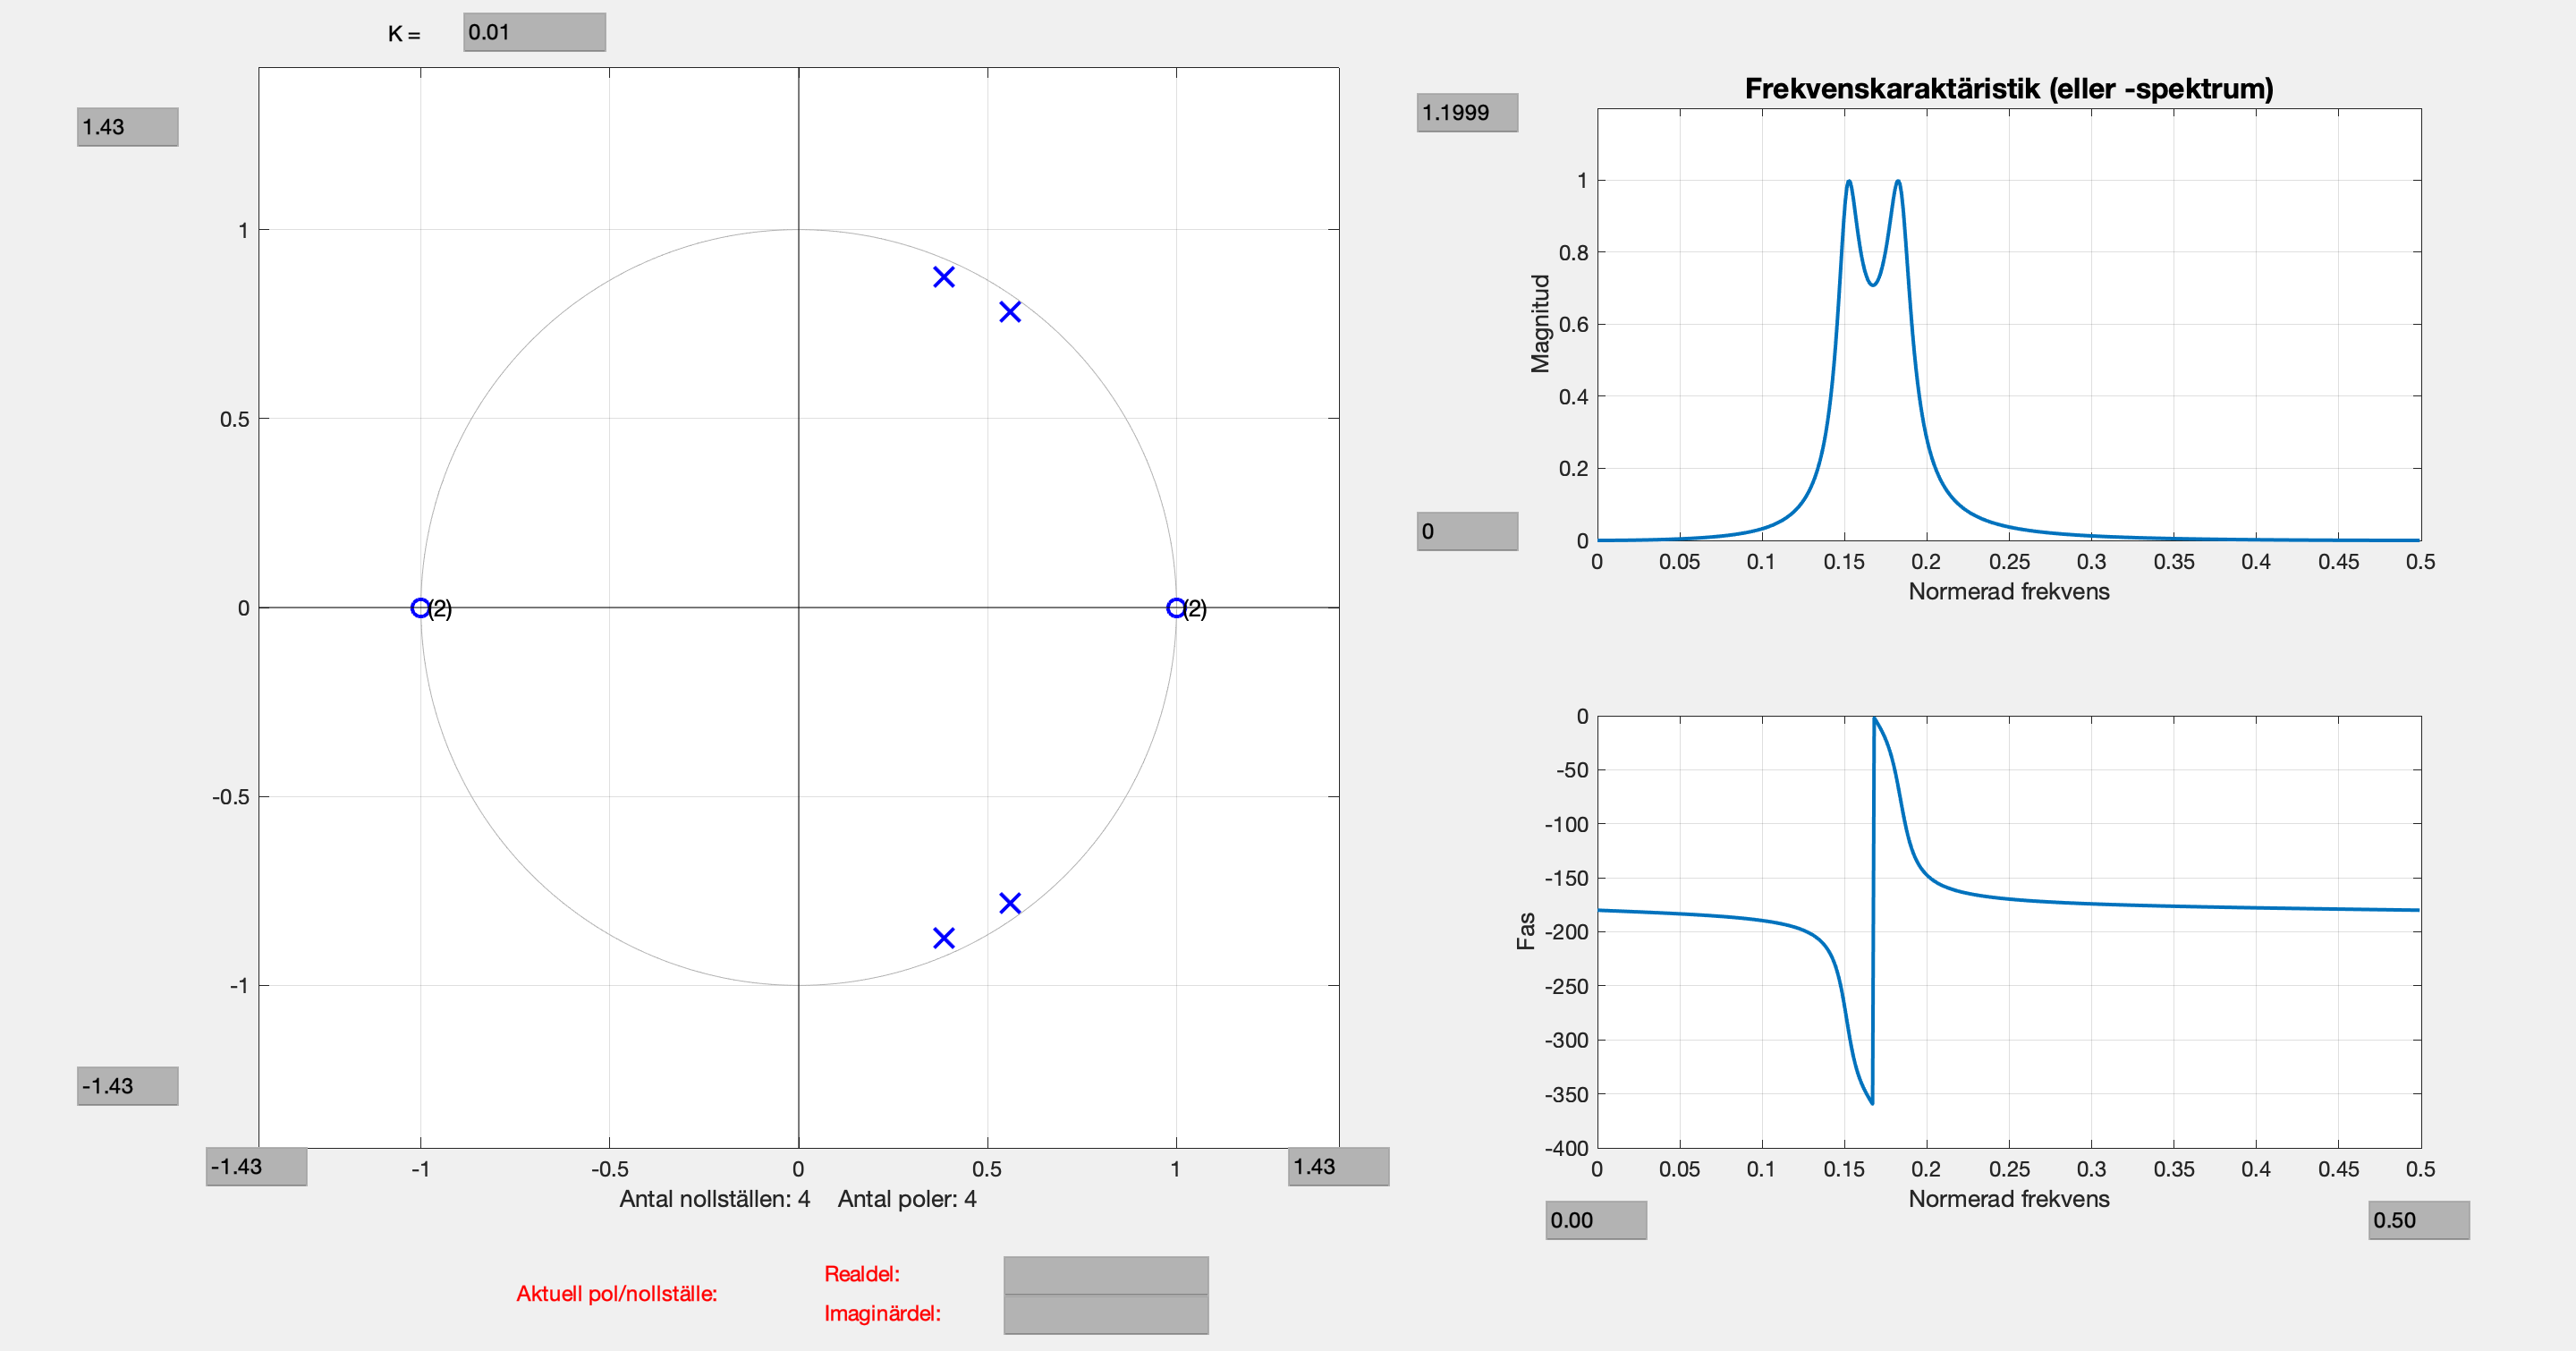

uppgift64c3

(*Anm: Vid det här laget bör du veta att om du öppnar/startar pzchange flera gånger, så är det bara den sist öppnade transformen som du kan manipulera i pzchange.*)

Hur väl filtrerar det tidsdiskreta BP-filtret den tidsdiskreta signalen $x\left\lbrack n\right\rbrack =$ `Dtoner`  jämfört med hur det tidskontinuerliga BP-filtret filtrerar den tidskontinuerliga signalen $x\left(t\right)=$`toner`? 

Kommentera särskilt de två filtrens frekvensegenskaper i passbandet, det undre spärrbandet och de övre spärrbandet.

☆  **Svar:**  Båda filtren filtrerar lika bra. Vi ser att den normerade grafen antar 0 då vi närmar oss 0,5. Den onormerade antar inte 0. 

### Uppgift 6.4d

Hur bra bandpassfiltrerar det tidskontinuerliga filtret respektive det tidsdiskreta filtret ovan om insignalen toner skulle innehålla en sinuskomponent på 5400 Hz?

(Notera att $5400>\frac{f_s }{2}$)

☆  **Svar:**  

Vi ser att $f_{\mathrm{Nyquist}} =\frac{6400}{2}=3200\mathrm{Hz}$ samt att $3200\not\succeq 5400$. Alltså finns det risk att filtrena inte fungerar bra för denna typ av komponenter. 

**Era lösta uppgifter i Laboration 4 ovan redovisas för assistenten under *****LABBPASS 4*****, i enlighet med anvisningarna i introduktionen inför Laboration 1. Laboration 1–3 ska vara redovisade *****innan***** Laboration 4 kan redovisas.**

**Det är lämpligt att ha med formelsamlingen vid redovisningstillfället, för att kunna relatera till samband och transformpar där.**

Till Innehållsförteckningen